# Gather files of operant and free session that have been manually curated

BasePath = '/Volumes/JulieE8T/';
[List2AudioPath, SessionType] = gather_audio_datapath(BasePath);

*** Gathering paths to audio reconly data ***
  -> Looking into  /Volumes/JulieE8T/LMC_CoEd...
    20190506
skipping, we only focus on recordings with implants
   20190507
skipping, we only focus on recordings with implants
   20190508
skipping, we only focus on recordings with implants
   20190509
skipping, we only focus on recordings with implants
   20190510
skipping, we only focus on recordings with implants
   20190513
skipping, we only focus on recordings with implants
   20190514
skipping, we only focus on recordings with implants
   20190515
skipping, we only focus on recordings with implants
   20190516
skipping, we only focus on recordings with implants
   20190517
skipping, we only focus on recordings with implants
   20190520
skipping, we only focus on recordings with implants
   20190521
skipping, we only focus on recordings with implants
   20190522
skipping, we only focus on recordings with implants
   20190523
skipping, we only focus on recordings with implants
   20190

   20190131
   20190201
   20190202
   20190204
   20190205
   20190206
   20190207
   20190208
   20190212
   20190213
   20190214

 76 files of operant sessions and 363 files of free recording sessions have been retrieved


Nsets = length(List2AudioPath);

## Gather data

WarningID = 'MATLAB:Python:UnsupportedLoad';
warning('off', WarningID)
Ncalls = 0;
NTrills = 0;
BatIDs = cell(1,Nsets);
Dates = cell(1,Nsets);
Mean_SpecMean_piezo = cell(1,Nsets);
Mean_Fund_piezo = cell(1,Nsets);
Mean_Amp_piezo = cell(1,Nsets);
Mean_Saliency_piezo = cell(1,Nsets);
Duration_ms = cell(1,Nsets);
SessionID = cell(1,Nsets);
Trills01 = cell(1,Nsets);
Filenames = cell(1,Nsets);
CuratedSetNumSeq = nan(Nsets,1);
CuratedSetFullSeq = nan(Nsets,1);
CuratedSetDate = nan(Nsets,1);
CallOnSetOffset = cell(1,Nsets);
CallOnSetOffsetBat = cell(1,Nsets);
CallOnSetOffsetSessionID = cell(1,Nsets);
CallOnSetOffsetDate = cell(1,Nsets);
for Seti=1:Nsets
    clear BioSoundFilenames
    fprintf(1,'Set %d/%d %s\n', Seti, Nsets, List2AudioPath{Seti})
    load(List2AudioPath{Seti}, 'BioSoundCalls', 'BioSoundFilenames', 'IndVocStartRaw_merged', 'IndVocStart_all', 'IndVocStop_all', 'BatID', 'LoggerName');
    load([List2AudioPath{Seti}(1:end-8) '.mat'], 'Voc_transc_time_refined', 'Piezo_FS')
    ALnames = fieldnames(Piezo_FS);
    if exist('BioSoundFilenames', 'var')
        VocInd1 = find(~cellfun('isempty',(BioSoundFilenames(:,1))));
        VocInd2 = find(~cellfun('isempty',(BioSoundCalls(:,1))));
        VocInd3 = find(~cellfun('isempty',(BioSoundCalls(:,2))));
        VocInd = intersect(intersect(VocInd1, VocInd2), VocInd3);
        NVoc = length(VocInd);
        Filenames{Seti} = cell(1,NVoc);
        BatIDs{Seti} = cell(1,NVoc);
        Dates{Seti} = cell(1,NVoc);
        Mean_SpecMean_piezo{Seti} = nan(1,NVoc);
        Mean_Fund_piezo{Seti} = nan(1,NVoc);
        Mean_Amp_piezo{Seti} = nan(1,NVoc);
        Mean_Saliency_piezo{Seti} = nan(1,NVoc);
        Duration_ms{Seti} = nan(1,NVoc);
        Trills01{Seti} = nan(1,NVoc);
        if strcmp(SessionType{Seti}, 'O')% operant session
            SessionID{Seti} = ones(1,NVoc);
        else
            SessionID{Seti} = zeros(1,NVoc);
        end
        for ii=1:NVoc
            vv=VocInd(ii);
            Ind_AL = strfind(BioSoundFilenames{vv,1},'_AL');
            Ind_Bat = strfind(BioSoundFilenames{vv,1}, '_Bat');
            Ind_voc = strfind(BioSoundFilenames{vv,1}, '_voc_');
            BatIDs{Seti}{ii} = BioSoundFilenames{vv,1}((Ind_Bat + 4):(Ind_AL-1));
            Dates{Seti}{ii} = BioSoundFilenames{vv,1}((Ind_voc-11) : (Ind_voc-6));
            Mean_SpecMean_piezo{Seti}(ii) = nanmean(BioSoundCalls{vv,2}.SpectralMean(~isnan(BioSoundCalls{vv,2}.sal)));
            if isnan(Mean_SpecMean_piezo{Seti}(ii))
                keyboard
            end
            Mean_Fund_piezo{Seti}(ii) = nanmean(BioSoundCalls{vv,2}.f0);
            Mean_Amp_piezo{Seti}(ii) = nanmean(BioSoundCalls{vv,2}.amp(~isnan(BioSoundCalls{vv,2}.sal)));
            Mean_Saliency_piezo{Seti}(ii) = BioSoundCalls{vv,2}.meansal;
            Trills01{Seti}(ii) = contains(BioSoundCalls{vv,1}.type, 'Tr');
            Duration_ms{Seti}(ii) = length(BioSoundCalls{vv,2}.amp);
            Filenames{Seti}{ii} = BioSoundFilenames{vv,2};
        end 
        Ncalls = NVoc + Ncalls;
        NTrills = sum(Trills01{Seti}) + NTrills;
        clear BioSoundFilenames
    end
    
    CuratedSetNumSeq(Seti) = length(IndVocStart_all);
    [~,Filename,~] = fileparts(List2AudioPath{Seti});
    CuratedSetDate(Seti) = str2double(Filename(1:6));
    
    NumCall = zeros(length(IndVocStart_all),1);
    for cc=1:length(IndVocStart_all)
        if ~isempty(IndVocStartRaw_merged{cc})
            for bb=1:length(IndVocStart_all{cc})
                if ~isempty(IndVocStartRaw_merged{cc}{bb})
                    NumCall(cc)=length(IndVocStart_all{cc}{bb})+NumCall(cc);
                end
            end
        end
    end
    CuratedSetFullSeq(Seti) = sum(NumCall>0);
    CallOnSetOffset{Seti} = nan(2,sum(NumCall));
    CallOnSetOffsetBat{Seti} = nan(1,sum(NumCall));
    if strcmp(SessionType{Seti}, 'O')% operant session
            CallOnSetOffsetSessionID{Seti} = ones(1,sum(NumCall));
        else
            CallOnSetOffsetSessionID{Seti} = zeros(1,sum(NumCall));
    end
    CallOnSetOffsetDate{Seti} = str2double(Filename(1:6)).* ones(1,sum(NumCall));
        
    CallCount = 0;
    for cc=1:length(IndVocStart_all)
        if ~isempty(IndVocStartRaw_merged{cc})
            for bb=1:length(IndVocStart_all{cc})
                if ~isempty(IndVocStartRaw_merged{cc}{bb})
                    for calli=1:length(IndVocStart_all{cc}{bb})
                        CallCount = CallCount + 1;
                        CallOnSetOffset{Seti}(1,CallCount) = IndVocStart_all{cc}{bb}(calli) + Voc_transc_time_refined(cc,1);
                        CallOnSetOffset{Seti}(2, CallCount) = IndVocStop_all{cc}{bb}(calli) + Voc_transc_time_refined(cc,1);
                        CallOnSetOffsetBat{Seti}(CallCount) = BatID{contains(LoggerName,ALnames{bb}(7:end))};
                        if isnan(CallOnSetOffsetBat{Seti}(CallCount))
                            keyboard
                        end
                    end
                end
            end
        end
    end
    if CallCount~=sum(NumCall)
        keyboard
    end
    
end 

Set 1/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190604/190604_1200_VocExtractData_200.mat
Set 2/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190604/190604_1636_VocExtractData1_200.mat
Set 3/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190604/190604_1636_VocExtractData2_200.mat


Set 4/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190604/190604_1636_VocExtractData3_200.mat


Set 5/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190604/190604_1636_VocExtractData4_200.mat


Set 6/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190605/190605_1006_VocExtractData_200.mat
Set 7/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190606/190606_1007_VocExtractData_200.mat
Set 8/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190606/190606_1408_VocExtractData_200.mat
Set 9/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190606/190606_1540_VocExtractData1_200.mat
Set 10/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190606/190606_1540_VocExtractData2_200.mat


Set 11/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190606/190606_1540_VocExtractData3_200.mat


Set 12/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190606/190606_1540_VocExtractData4_200.mat


Set 13/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190606/190606_1540_VocExtractData5_200.mat


Set 14/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190607/190607_0827_VocExtractData_200.mat
Set 15/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190607/190607_1301_VocExtractData1_200.mat
Set 16/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190607/190607_1301_VocExtractData2_200.mat


Set 17/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190607/190607_1301_VocExtractData3_200.mat


Set 18/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190607/190607_1301_VocExtractData4_200.mat


Set 19/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190607/190607_1301_VocExtractData5_200.mat


Set 20/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190607/190607_1301_VocExtractData6_200.mat


Set 21/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190610/190610_0953_VocExtractData_200.mat
Set 22/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190610/190610_1442_VocExtractData1_200.mat
Set 23/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190610/190610_1442_VocExtractData2_200.mat


Set 24/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190610/190610_1442_VocExtractData3_200.mat


Set 25/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190610/190610_1442_VocExtractData4_200.mat


Set 26/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190610/190610_1442_VocExtractData5_200.mat


Set 27/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190610/190610_1442_VocExtractData6_200.mat


Set 28/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190610/190610_1442_VocExtractData7_200.mat


Set 29/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190611/190611_1023_VocExtractData_200.mat
Set 30/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190611/190611_1447_VocExtractData1_200.mat
Set 31/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190611/190611_1447_VocExtractData2_200.mat


Set 32/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190611/190611_1447_VocExtractData3_200.mat


Set 33/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190611/190611_1447_VocExtractData4_200.mat


Set 34/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190611/190611_1447_VocExtractData5_200.mat


Set 35/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190611/190611_1447_VocExtractData6_200.mat


Set 36/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190611/190611_1447_VocExtractData7_200.mat


Set 37/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190612/190612_1030_VocExtractData_200.mat
Set 38/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190612/190612_1251_VocExtractData_200.mat
Set 39/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190612/190612_1438_VocExtractData1_200.mat
Set 40/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190612/190612_1438_VocExtractData2_200.mat


Set 41/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190612/190612_1438_VocExtractData3_200.mat


Set 42/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190612/190612_1438_VocExtractData4_200.mat


Set 43/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190612/190612_1438_VocExtractData5_200.mat


Set 44/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190612/190612_1438_VocExtractData6_200.mat


Set 45/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190612/190612_1438_VocExtractData7_200.mat


Set 46/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190612/190612_1438_VocExtractData8_200.mat


Set 47/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190612/190612_1438_VocExtractData9_200.mat


Set 48/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190613/190613_0955_VocExtractData_200.mat
Set 49/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190613/190613_1404_VocExtractData10_200.mat


Set 50/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190613/190613_1404_VocExtractData11_200.mat


Set 51/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190613/190613_1404_VocExtractData12_200.mat


Set 52/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190613/190613_1404_VocExtractData13_200.mat


Set 53/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190613/190613_1404_VocExtractData1_200.mat
Set 54/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190613/190613_1404_VocExtractData2_200.mat


Set 55/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190613/190613_1404_VocExtractData3_200.mat


Set 56/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190613/190613_1404_VocExtractData4_200.mat


Set 57/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190613/190613_1404_VocExtractData5_200.mat


Set 58/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190613/190613_1404_VocExtractData6_200.mat


Set 59/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190613/190613_1404_VocExtractData7_200.mat


Set 60/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190613/190613_1404_VocExtractData8_200.mat


Set 61/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190613/190613_1404_VocExtractData9_200.mat


Set 62/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190614/190614_0951_VocExtractData_200.mat
Set 63/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190614/190614_1432_VocExtractData1_200.mat
Set 64/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190614/190614_1432_VocExtractData2_200.mat


Set 65/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190614/190614_1432_VocExtractData3_200.mat


Set 66/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190614/190614_1432_VocExtractData4_200.mat


Set 67/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190614/190614_1432_VocExtractData5_200.mat


Set 68/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190614/190614_1432_VocExtractData6_200.mat


Set 69/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190614/190614_1432_VocExtractData7_200.mat


Set 70/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190614/190614_1432_VocExtractData8_200.mat


Set 71/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190614/190614_1432_VocExtractData9_200.mat


Set 72/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190616/190616_1258_VocExtractData_200.mat
Set 73/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190616/190616_1725_VocExtractData1_200.mat
Set 74/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190616/190616_1725_VocExtractData2_200.mat


Set 75/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190616/190616_1725_VocExtractData3_200.mat


Set 76/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190616/190616_1725_VocExtractData4_200.mat


Set 77/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190616/190616_1725_VocExtractData5_200.mat


Set 78/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190616/190616_1725_VocExtractData6_200.mat


Set 79/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190616/190616_1725_VocExtractData7_200.mat


Set 80/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190617/190617_1053_VocExtractData_200.mat
Set 81/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190617/190617_1518_VocExtractData1_200.mat
Set 82/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190617/190617_1518_VocExtractData2_200.mat


Set 83/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190617/190617_1518_VocExtractData3_200.mat


Set 84/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190617/190617_1518_VocExtractData4_200.mat


Set 85/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190617/190617_1518_VocExtractData5_200.mat


Set 86/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190617/190617_1518_VocExtractData6_200.mat


Set 87/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190617/190617_1518_VocExtractData7_200.mat


Set 88/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190617/190617_1518_VocExtractData8_200.mat


Set 89/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190618/190618_1028_VocExtractData_200.mat
Set 90/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190618/190618_1454_VocExtractData1_200.mat
Set 91/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190618/190618_1454_VocExtractData2_200.mat


Set 92/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190618/190618_1454_VocExtractData3_200.mat


Set 93/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190618/190618_1454_VocExtractData4_200.mat


Set 94/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190618/190618_1454_VocExtractData5_200.mat


Set 95/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190618/190618_1454_VocExtractData6_200.mat


Set 96/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190618/190618_1454_VocExtractData7_200.mat


Set 97/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190619/190619_1011_VocExtractData_200.mat
Set 98/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190620/190620_1005_VocExtractData_200.mat
Set 99/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190620/190620_1414_VocExtractData1_200.mat
Set 100/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190620/190620_1414_VocExtractData2_200.mat


Set 101/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190620/190620_1414_VocExtractData3_200.mat


Set 102/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190620/190620_1414_VocExtractData4_200.mat


Set 103/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190620/190620_1414_VocExtractData5_200.mat


Set 104/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190620/190620_1414_VocExtractData6_200.mat


Set 105/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190620/190620_1414_VocExtractData7_200.mat


Set 106/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190621/190621_0926_VocExtractData_200.mat
Set 107/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190621/190621_1337_VocExtractData1_200.mat
Set 108/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190621/190621_1337_VocExtractData2_200.mat


Set 109/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190621/190621_1337_VocExtractData3_200.mat


Set 110/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190621/190621_1337_VocExtractData4_200.mat


Set 111/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190621/190621_1337_VocExtractData5_200.mat


Set 112/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190621/190621_1337_VocExtractData6_200.mat


Set 113/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190621/190621_1337_VocExtractData7_200.mat


Set 114/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190622/190622_1030_VocExtractData_200.mat
Set 115/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190622/190622_1440_VocExtractData1_200.mat
Set 116/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190622/190622_1440_VocExtractData2_200.mat


Set 117/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190623/190623_0950_VocExtractData_200.mat
Set 118/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190623/190623_1401_VocExtractData1_200.mat
Set 119/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190623/190623_1401_VocExtractData2_200.mat


Set 120/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190623/190623_1401_VocExtractData3_200.mat


Set 121/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190623/190623_1401_VocExtractData4_200.mat


Set 122/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190623/190623_1401_VocExtractData5_200.mat


Set 123/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190623/190623_1401_VocExtractData6_200.mat


Set 124/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190623/190623_1401_VocExtractData7_200.mat


Set 125/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190624/190624_0955_VocExtractData_200.mat
Set 126/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190624/190624_1416_VocExtractData1_200.mat
Set 127/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190624/190624_1429_VocExtractData10_200.mat


Set 128/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190624/190624_1429_VocExtractData1_200.mat
Set 129/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190624/190624_1429_VocExtractData2_200.mat


Set 130/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190624/190624_1429_VocExtractData3_200.mat


Set 131/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190624/190624_1429_VocExtractData4_200.mat


Set 132/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190624/190624_1429_VocExtractData5_200.mat


Set 133/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190624/190624_1429_VocExtractData6_200.mat


Set 134/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190624/190624_1429_VocExtractData7_200.mat


Set 135/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190624/190624_1429_VocExtractData8_200.mat


Set 136/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190624/190624_1429_VocExtractData9_200.mat


Set 137/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190625/190625_1039_VocExtractData_200.mat
Set 138/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190625/190625_1447_VocExtractData1_200.mat
Set 139/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190625/190625_1447_VocExtractData2_200.mat


Set 140/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190625/190625_1447_VocExtractData3_200.mat


Set 141/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190625/190625_1447_VocExtractData4_200.mat


Set 142/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190625/190625_1447_VocExtractData5_200.mat


Set 143/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190625/190625_1447_VocExtractData6_200.mat


Set 144/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190625/190625_1447_VocExtractData7_200.mat


Set 145/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190625/190625_1447_VocExtractData8_200.mat


Set 146/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190626/190626_1036_VocExtractData_200.mat
Set 147/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190626/190626_1516_VocExtractData1_200.mat
Set 148/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190626/190626_1516_VocExtractData2_200.mat


Set 149/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190626/190626_1516_VocExtractData3_200.mat


Set 150/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190626/190626_1516_VocExtractData4_200.mat


Set 151/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190626/190626_1516_VocExtractData5_200.mat


Set 152/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190626/190626_1516_VocExtractData6_200.mat


Set 153/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190626/190626_1516_VocExtractData7_200.mat


Set 154/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190626/190626_1516_VocExtractData8_200.mat


Set 155/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190626/190626_1516_VocExtractData9_200.mat


Set 156/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190627/190627_1048_VocExtractData_200.mat
Set 157/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190627/190627_1511_VocExtractData1_200.mat
Set 158/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190627/190627_1511_VocExtractData2_200.mat


Set 159/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190627/190627_1511_VocExtractData3_200.mat


Set 160/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190627/190627_1511_VocExtractData4_200.mat


Set 161/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190627/190627_1511_VocExtractData5_200.mat


Set 162/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190627/190627_1511_VocExtractData6_200.mat


Set 163/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190627/190627_1511_VocExtractData7_200.mat


Set 164/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190628/190628_0950_VocExtractData_200.mat
Set 165/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190628/190628_1400_VocExtractData10_200.mat


Set 166/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190628/190628_1400_VocExtractData1_200.mat
Set 167/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190628/190628_1400_VocExtractData2_200.mat


Set 168/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190628/190628_1400_VocExtractData3_200.mat


Set 169/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190628/190628_1400_VocExtractData4_200.mat


Set 170/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190628/190628_1400_VocExtractData5_200.mat


Set 171/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190628/190628_1400_VocExtractData6_200.mat


Set 172/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190628/190628_1400_VocExtractData7_200.mat


Set 173/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190628/190628_1400_VocExtractData8_200.mat


Set 174/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190628/190628_1400_VocExtractData9_200.mat


Set 175/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190629/190629_0947_VocExtractData_200.mat
Set 176/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190629/190629_1356_VocExtractData10_200.mat


Set 177/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190629/190629_1356_VocExtractData1_200.mat
Set 178/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190629/190629_1356_VocExtractData2_200.mat


Set 179/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190629/190629_1356_VocExtractData3_200.mat


Set 180/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190629/190629_1356_VocExtractData4_200.mat


Set 181/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190629/190629_1356_VocExtractData5_200.mat


Set 182/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190629/190629_1356_VocExtractData6_200.mat


Set 183/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190629/190629_1356_VocExtractData7_200.mat


Set 184/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190629/190629_1356_VocExtractData8_200.mat


Set 185/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190629/190629_1356_VocExtractData9_200.mat


Set 186/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190630/190630_1019_VocExtractData_200.mat
Set 187/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190630/190630_1427_VocExtractData1_200.mat
Set 188/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190630/190630_1427_VocExtractData2_200.mat


Set 189/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190630/190630_1427_VocExtractData3_200.mat


Set 190/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190630/190630_1427_VocExtractData4_200.mat


Set 191/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190630/190630_1427_VocExtractData5_200.mat


Set 192/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190630/190630_1427_VocExtractData6_200.mat


Set 193/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190630/190630_1427_VocExtractData7_200.mat


Set 194/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190701/190701_0955_VocExtractData_200.mat
Set 195/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190701/190701_1414_VocExtractData1_200.mat
Set 196/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190701/190701_1414_VocExtractData2_200.mat


Set 197/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190701/190701_1414_VocExtractData3_200.mat


Set 198/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190701/190701_1414_VocExtractData4_200.mat


Set 199/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190701/190701_1414_VocExtractData5_200.mat


Set 200/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190701/190701_1414_VocExtractData6_200.mat


Set 201/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190701/190701_1414_VocExtractData7_200.mat


Set 202/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190701/190701_1414_VocExtractData8_200.mat


Set 203/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190702/190702_1018_VocExtractData_200.mat
Set 204/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190702/190702_1425_VocExtractData1_200.mat
Set 205/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190702/190702_1425_VocExtractData2_200.mat


Set 206/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190702/190702_1425_VocExtractData3_200.mat


Set 207/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190702/190702_1425_VocExtractData4_200.mat


Set 208/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190702/190702_1425_VocExtractData5_200.mat


Set 209/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190702/190702_1425_VocExtractData6_200.mat


Set 210/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190702/190702_1425_VocExtractData7_200.mat


Set 211/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190702/190702_1425_VocExtractData8_200.mat


Set 212/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190704/190704_1018_VocExtractData_200.mat
Set 213/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190704/190704_1426_VocExtractData1_200.mat
Set 214/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190704/190704_1426_VocExtractData2_200.mat


Set 215/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190704/190704_1426_VocExtractData3_200.mat


Set 216/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190704/190704_1426_VocExtractData4_200.mat


Set 217/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190704/190704_1426_VocExtractData5_200.mat


Set 218/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190704/190704_1426_VocExtractData6_200.mat


Set 219/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190704/190704_1426_VocExtractData7_200.mat


Set 220/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190704/190704_1426_VocExtractData8_200.mat


Set 221/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190704/190704_1426_VocExtractData9_200.mat


Set 222/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190705/190705_1051_VocExtractData_200.mat
Set 223/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190705/190705_1504_VocExtractData10_200.mat


Set 224/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190705/190705_1504_VocExtractData11_200.mat


Set 225/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190705/190705_1504_VocExtractData1_200.mat
Set 226/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190705/190705_1504_VocExtractData2_200.mat


Set 227/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190705/190705_1504_VocExtractData3_200.mat


Set 228/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190705/190705_1504_VocExtractData4_200.mat


Set 229/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190705/190705_1504_VocExtractData5_200.mat


Set 230/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190705/190705_1504_VocExtractData6_200.mat


Set 231/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190705/190705_1504_VocExtractData7_200.mat


Set 232/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190705/190705_1504_VocExtractData8_200.mat


Set 233/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190705/190705_1504_VocExtractData9_200.mat


Set 234/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190706/190706_1118_VocExtractData_200.mat
Set 235/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190706/190706_1528_VocExtractData10_200.mat


Set 236/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190706/190706_1528_VocExtractData11_200.mat


Set 237/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190706/190706_1528_VocExtractData12_200.mat


Set 238/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190706/190706_1528_VocExtractData13_200.mat


Set 239/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190706/190706_1528_VocExtractData1_200.mat
Set 240/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190706/190706_1528_VocExtractData2_200.mat


Set 241/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190706/190706_1528_VocExtractData3_200.mat


Set 242/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190706/190706_1528_VocExtractData4_200.mat


Set 243/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190706/190706_1528_VocExtractData5_200.mat


Set 244/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190706/190706_1528_VocExtractData6_200.mat


Set 245/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190706/190706_1528_VocExtractData7_200.mat


Set 246/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190706/190706_1528_VocExtractData8_200.mat


Set 247/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190706/190706_1528_VocExtractData9_200.mat


Set 248/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190707/190707_1008_VocExtractData_200.mat
Set 249/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190707/190707_1419_VocExtractData1_200.mat
Set 250/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190707/190707_1419_VocExtractData2_200.mat


Set 251/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190707/190707_1419_VocExtractData3_200.mat


Set 252/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190707/190707_1419_VocExtractData4_200.mat


Set 253/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190707/190707_1419_VocExtractData5_200.mat


Set 254/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190707/190707_1419_VocExtractData6_200.mat


Set 255/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190707/190707_1419_VocExtractData7_200.mat


Set 256/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190707/190707_1419_VocExtractData8_200.mat


Set 257/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190707/190707_1419_VocExtractData9_200.mat


Set 258/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190708/190708_1002_VocExtractData_200.mat
Set 259/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190708/190708_1417_VocExtractData1_200.mat
Set 260/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190708/190708_1417_VocExtractData2_200.mat


Set 261/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190708/190708_1417_VocExtractData3_200.mat


Set 262/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190708/190708_1417_VocExtractData4_200.mat


Set 263/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190708/190708_1417_VocExtractData5_200.mat


Set 264/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190708/190708_1417_VocExtractData6_200.mat


Set 265/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190708/190708_1417_VocExtractData7_200.mat


Set 266/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190708/190708_1417_VocExtractData8_200.mat


Set 267/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190708/190708_1417_VocExtractData9_200.mat


Set 268/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190710/190710_0943_VocExtractData_200.mat
Set 269/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190710/190710_1416_VocExtractData1_200.mat
Set 270/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190710/190710_1416_VocExtractData2_200.mat


Set 271/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190710/190710_1416_VocExtractData3_200.mat


Set 272/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190710/190710_1416_VocExtractData4_200.mat


Set 273/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190710/190710_1416_VocExtractData5_200.mat


Set 274/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190710/190710_1453_VocExtractData1_200.mat
Set 275/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190710/190710_1453_VocExtractData2_200.mat


Set 276/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190710/190710_1453_VocExtractData3_200.mat


Set 277/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190710/190710_1453_VocExtractData4_200.mat


Set 278/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190710/190710_1453_VocExtractData5_200.mat


Set 279/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190710/190710_1453_VocExtractData6_200.mat


Set 280/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190711/190711_0930_VocExtractData_200.mat
Set 281/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190711/190711_1406_VocExtractData1_200.mat
Set 282/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190711/190711_1406_VocExtractData2_200.mat


Set 283/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190711/190711_1406_VocExtractData3_200.mat


Set 284/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190711/190711_1406_VocExtractData4_200.mat


Set 285/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190711/190711_1406_VocExtractData5_200.mat


Set 286/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190711/190711_1406_VocExtractData6_200.mat


Set 287/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190711/190711_1406_VocExtractData7_200.mat


Set 288/439 /Volumes/JulieE8T/LMC_CoEd/logger/20190712/190712_0859_VocExtractData_200.mat


Set 289/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190116/190116_1028_VocExtractData1_200.mat
Set 290/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190116/190116_1058_VocExtractData1_200.mat
Set 291/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190116/190116_1110_VocExtractData1_200.mat
Set 292/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190116/190116_1126_VocExtractData1_200.mat
Set 293/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190117/190117_1008_VocExtractData1_200.mat
Set 294/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190117/190117_1355_VocExtractData1_200.mat
Set 295/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190117/190117_1355_VocExtractData2_200.mat


Set 296/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190117/190117_1355_VocExtractData3_200.mat


Set 297/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190118/190118_1013_VocExtractData1_200.mat
Set 298/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190118/190118_1027_VocExtractData1_200.mat
Set 299/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190118/190118_1027_VocExtractData2_200.mat


Set 300/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190118/190118_1200_VocExtractData1_200.mat
Set 301/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190118/190118_1200_VocExtractData2_200.mat


Set 302/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190118/190118_1200_VocExtractData3_200.mat


Set 303/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190118/190118_1200_VocExtractData4_200.mat


Set 304/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190118/190118_1200_VocExtractData5_200.mat


Set 305/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190118/190118_1200_VocExtractData6_200.mat


Set 306/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190119/190119_1158_VocExtractData1_200.mat
Set 307/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190119/190119_1551_VocExtractData1_200.mat
Set 308/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190119/190119_1551_VocExtractData2_200.mat


Set 309/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190119/190119_1551_VocExtractData3_200.mat


Set 310/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190119/190119_1551_VocExtractData4_200.mat


Set 311/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190119/190119_1551_VocExtractData5_200.mat


Set 312/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190120/190120_1208_VocExtractData1_200.mat
Set 313/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190120/190120_1208_VocExtractData2_200.mat


Set 314/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190120/190120_1641_VocExtractData1_200.mat
Set 315/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190120/190120_1641_VocExtractData2_200.mat


Set 316/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190120/190120_1641_VocExtractData3_200.mat


Set 317/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190120/190120_1641_VocExtractData4_200.mat


Set 318/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190120/190120_1641_VocExtractData5_200.mat


Set 319/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190120/190120_1641_VocExtractData6_200.mat


Set 320/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190120/190120_1641_VocExtractData7_200.mat


Set 321/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190123/190123_0943_VocExtractData1_200.mat
Set 322/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190123/190123_0943_VocExtractData2_200.mat


Set 323/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190123/190123_1404_VocExtractData1_200.mat
Set 324/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190123/190123_1404_VocExtractData2_200.mat


Set 325/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190123/190123_1404_VocExtractData3_200.mat


Set 326/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190123/190123_1404_VocExtractData4_200.mat


Set 327/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190123/190123_1404_VocExtractData5_200.mat


Set 328/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190124/190124_0957_VocExtractData1_200.mat
Set 329/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190124/190124_1401_VocExtractData1_200.mat
Set 330/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190124/190124_1401_VocExtractData2_200.mat


Set 331/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190124/190124_1401_VocExtractData3_200.mat


Set 332/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190124/190124_1401_VocExtractData4_200.mat


Set 333/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190124/190124_1401_VocExtractData5_200.mat


Set 334/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190124/190124_1401_VocExtractData6_200.mat


Set 335/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190124/190124_1401_VocExtractData7_200.mat


Set 336/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190124/190124_1401_VocExtractData8_200.mat


Set 337/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190125/190125_0925_VocExtractData1_200.mat
Set 338/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190125/190125_1358_VocExtractData1_200.mat
Set 339/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190125/190125_1358_VocExtractData2_200.mat


Set 340/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190125/190125_1358_VocExtractData3_200.mat


Set 341/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190125/190125_1358_VocExtractData4_200.mat


Set 342/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190129/190129_1023_VocExtractData1_200.mat
Set 343/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190129/190129_1023_VocExtractData2_200.mat


Set 344/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190129/190129_1304_VocExtractData1_200.mat
Set 345/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190129/190129_1304_VocExtractData2_200.mat


Set 346/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190129/190129_1304_VocExtractData3_200.mat


Set 347/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190129/190129_1304_VocExtractData4_200.mat


Set 348/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190130/190130_1007_VocExtractData1_200.mat
Set 349/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190130/190130_1007_VocExtractData2_200.mat


Set 350/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190130/190130_1425_VocExtractData1_200.mat
Set 351/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190130/190130_1425_VocExtractData2_200.mat


Set 352/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190130/190130_1425_VocExtractData3_200.mat


Set 353/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190130/190130_1425_VocExtractData4_200.mat


Set 354/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190130/190130_1425_VocExtractData5_200.mat


Set 355/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190130/190130_1425_VocExtractData6_200.mat


Set 356/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190130/190130_1425_VocExtractData7_200.mat


Set 357/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190131/190131_1108_VocExtractData1_200.mat
Set 358/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190131/190131_1108_VocExtractData2_200.mat


Set 359/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190201/190201_1023_VocExtractData1_200.mat
Set 360/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190201/190201_1023_VocExtractData2_200.mat


Set 361/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190201/190201_1411_VocExtractData10_200.mat


Set 362/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190201/190201_1411_VocExtractData11_200.mat


Set 363/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190201/190201_1411_VocExtractData1_200.mat
Set 364/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190201/190201_1411_VocExtractData2_200.mat


Set 365/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190201/190201_1411_VocExtractData3_200.mat


Set 366/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190201/190201_1411_VocExtractData4_200.mat


Set 367/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190201/190201_1411_VocExtractData5_200.mat


Set 368/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190201/190201_1411_VocExtractData6_200.mat


Set 369/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190201/190201_1411_VocExtractData7_200.mat


Set 370/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190201/190201_1411_VocExtractData8_200.mat


Set 371/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190201/190201_1411_VocExtractData9_200.mat


Set 372/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190202/190202_1046_VocExtractData1_200.mat
Set 373/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190202/190202_1046_VocExtractData2_200.mat


Set 374/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190202/190202_1313_VocExtractData1_200.mat
Set 375/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190202/190202_1525_VocExtractData1_200.mat
Set 376/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190204/190204_1051_VocExtractData1_200.mat
Set 377/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190204/190204_1051_VocExtractData2_200.mat


Set 378/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190204/190204_1504_VocExtractData1_200.mat
Set 379/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190204/190204_1504_VocExtractData2_200.mat


Set 380/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190204/190204_1504_VocExtractData3_200.mat


Set 381/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190204/190204_1504_VocExtractData4_200.mat


Set 382/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190204/190204_1504_VocExtractData5_200.mat


Set 383/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190204/190204_1504_VocExtractData6_200.mat


Set 384/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190205/190205_1140_VocExtractData1_200.mat
Set 385/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190205/190205_1140_VocExtractData2_200.mat


Set 386/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190205/190205_1556_VocExtractData1_200.mat
Set 387/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190205/190205_1556_VocExtractData2_200.mat


Set 388/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190205/190205_1556_VocExtractData3_200.mat


Set 389/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190205/190205_1556_VocExtractData4_200.mat


Set 390/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190205/190205_1556_VocExtractData5_200.mat


Set 391/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1024_VocExtractData1_200.mat
Set 392/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1024_VocExtractData2_200.mat


Set 393/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData10_200.mat


Set 394/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData11_200.mat


Set 395/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData12_200.mat


Set 396/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData13_200.mat


Set 397/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData14_200.mat


Set 398/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData15_200.mat


Set 399/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData16_200.mat


Set 400/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData17_200.mat


Set 401/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData18_200.mat


Set 402/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData19_200.mat


Set 403/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData1_200.mat
Set 404/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData20_200.mat


Set 405/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData21_200.mat


Set 406/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData22_200.mat


Set 407/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData23_200.mat


Set 408/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData24_200.mat


Set 409/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData25_200.mat


Set 410/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData2_200.mat


Set 411/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData3_200.mat


Set 412/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData4_200.mat


Set 413/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData5_200.mat


Set 414/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData6_200.mat


Set 415/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData7_200.mat


Set 416/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData8_200.mat


Set 417/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190206/190206_1402_VocExtractData9_200.mat


Set 418/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190207/190207_1136_VocExtractData1_200.mat
Set 419/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190207/190207_1136_VocExtractData2_200.mat


Set 420/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190207/190207_1545_VocExtractData10_200.mat


Set 421/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190207/190207_1545_VocExtractData1_200.mat
Set 422/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190207/190207_1545_VocExtractData2_200.mat


Set 423/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190207/190207_1545_VocExtractData3_200.mat


Set 424/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190207/190207_1545_VocExtractData4_200.mat


Set 425/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190207/190207_1545_VocExtractData5_200.mat


Set 426/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190207/190207_1545_VocExtractData6_200.mat


Set 427/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190207/190207_1545_VocExtractData7_200.mat


Set 428/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190207/190207_1545_VocExtractData8_200.mat


Set 429/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190207/190207_1545_VocExtractData9_200.mat


Set 430/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190208/190208_1018_VocExtractData1_200.mat
Set 431/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190208/190208_1405_VocExtractData1_200.mat
Set 432/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190208/190208_1405_VocExtractData2_200.mat


Set 433/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190208/190208_1405_VocExtractData3_200.mat


Set 434/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190208/190208_1405_VocExtractData4_200.mat


Set 435/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190212/190212_1033_VocExtractData1_200.mat
Set 436/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190212/190212_1033_VocExtractData2_200.mat


Set 437/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190213/190213_1101_VocExtractData1_200.mat
Set 438/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190213/190213_1101_VocExtractData2_200.mat


Set 439/439 /Volumes/JulieE8T/LMC_HoHa/logger/20190214/190214_1130_VocExtractData1_200.mat


warning('on', WarningID)
BatIDs = [BatIDs{:}]';
Dates = [Dates{:}]';
Mean_SpecMean_piezo = [Mean_SpecMean_piezo{:}]';
Mean_Fund_piezo = [Mean_Fund_piezo{:}]';
Mean_Amp_piezo = [Mean_Amp_piezo{:}]';
Mean_Saliency_piezo = [Mean_Saliency_piezo{:}]';
SessionID = [SessionID{:}]';
Trills01 = [Trills01{:}]';
Filenames = [Filenames{:}]';
Duration_ms = [Duration_ms{:}]';
CallOnSetOffset = [CallOnSetOffset{:}]';
CallOnSetOffsetBat = [CallOnSetOffsetBat{:}]';
CallOnSetOffsetDate = [CallOnSetOffsetDate{:}]';
CallOnSetOffsetSessionID = [CallOnSetOffsetSessionID{:}]';

## Investigate some statistics (nb of calls...)

Number of sequences per day

Datex = unique(str2double(Dates));
CuratedDateSeqFree = nan(2,length(Datex));
CuratedDateSeqOperant = nan(2,length(Datex));
for dd = 1:length(Datex)
    FreeInd = logical((CuratedSetDate==Datex(dd)) .* (~contains(SessionType, 'O')));
    CuratedDateSeqFree(1,dd) = sum(CuratedSetNumSeq(FreeInd)) - sum(CuratedSetFullSeq(FreeInd)); % empty seq
    CuratedDateSeqFree(2,dd) = sum(CuratedSetFullSeq(FreeInd)); % seq with calls
    OpInd = logical((CuratedSetDate==Datex(dd)) .* (contains(SessionType, 'O')));
    CuratedDateSeqOperant(1,dd) = sum(CuratedSetNumSeq(OpInd)) - sum(CuratedSetFullSeq(OpInd)); % empty seq
    CuratedDateSeqOperant(2,dd) = sum(CuratedSetFullSeq(OpInd)); % seq with calls
end

% Number of calls per bat and Nb calls per bat and per day
FreeSessionNb = 0;
OpSessionNb = 0;
BatIDx = unique(str2double(BatIDs));
Datex = unique(str2double(Dates));
CountByID = nan(length(BatIDx),2);
DurationByID = nan(length(BatIDx),2);
CountByIDAndDateOperant = nan(length(BatIDx),length(Datex));
DurationByIDAndDateOperant = nan(length(BatIDx),length(Datex));
CountByIDAndDateFree = nan(length(BatIDx),length(Datex));
DurationByIDAndDateFree = nan(length(BatIDx),length(Datex));
for bb=1:length(BatIDx)
    CountByID(bb,1) = sum(str2double(BatIDs(logical(SessionID)))==BatIDx(bb));
    CountByID(bb,2) = sum(str2double(BatIDs(~SessionID))==BatIDx(bb));
    DurationByID(bb,1) = sum(Duration_ms(str2double(BatIDs(logical(SessionID)))==BatIDx(bb)));
    DurationByID(bb,2) = sum(Duration_ms(str2double(BatIDs(~SessionID))==BatIDx(bb)));

    for dd = 1:length(Datex)
        LogicalBatIDOp = logical((str2double(BatIDs)==BatIDx(bb)) .* SessionID);
        if sum(LogicalBatIDOp) % This Bat vocalized during Operant sessions
            TotCallsOp = sum(str2double(Dates(LogicalBatIDOp)) == Datex(dd));
            if TotCallsOp~=0 % Let's keep the value to Nan on days where there is no call (mots likely this bat was not recorded on that day)
                CountByIDAndDateOperant(bb,dd) = TotCallsOp;
                DurationByIDAndDateOperant(bb,dd) = sum(Duration_ms(str2double(Dates(LogicalBatIDOp)) == Datex(dd)));
            end
        end
        LogicalBatIDFr = logical((str2double(BatIDs)==BatIDx(bb)) .* ~SessionID);
        TotCallsFree = sum(str2double(Dates(LogicalBatIDFr)) == Datex(dd));
        if TotCallsFree ~= 0
            CountByIDAndDateFree(bb,dd) = TotCallsFree;
            DurationByIDAndDateFree(bb,dd) = sum(Duration_ms(str2double(Dates(LogicalBatIDFr)) == Datex(dd)));
        end
        % Count the number of sessions
        if bb==1
            if any(str2double(Dates(logical(SessionID))) == Datex(dd))
                OpSessionNb  = OpSessionNb +1;
            end
            if any(str2double(Dates(~SessionID)) == Datex(dd))
                FreeSessionNb  = FreeSessionNb +1;
            end
        end
            
    end
    
end

figure();
BAR = bar(CountByID);
BAR(1).Parent.XTick = 1:length(unique(BatIDs));
BAR(1).Parent.XTickLabel = unique(BatIDs);
title(sprintf('Total number of calls over %d free sessions and %d operant sessions', FreeSessionNb, OpSessionNb))
legend('Operant', 'Free', 'Location', 'best')
xlabel('BatID')
ylabel('# calls')


figure()
BAR2 = bar(mean(CountByIDAndDateFree,2,'omitnan'));
BAR2.Parent.XTick = 1:length(unique(BatIDs));
BAR2.Parent.XTickLabel = unique(BatIDs);
hold on
errorbar(1:length(unique(BatIDs)),mean(CountByIDAndDateFree,2,'omitnan'), 2*std(CountByIDAndDateFree,[],2,'omitnan')./sum(~isnan(CountByIDAndDateFree),2).^0.5, 'ko')
hold off
title('Average number of calls per Free session')
xlabel('BatID')
ylabel('# calls')

% Focusing on Implanted bats
UBatIDs = unique(BatIDs);
ImpInd = [2 6:8];
fprintf(1,'These are the implanted bats:\n')

These are the implanted bats:


UBatIDs(ImpInd)

ans = 4×1 cell array
    {'11689'}
    {'59834'}
    {'59882'}
    {'65701'}


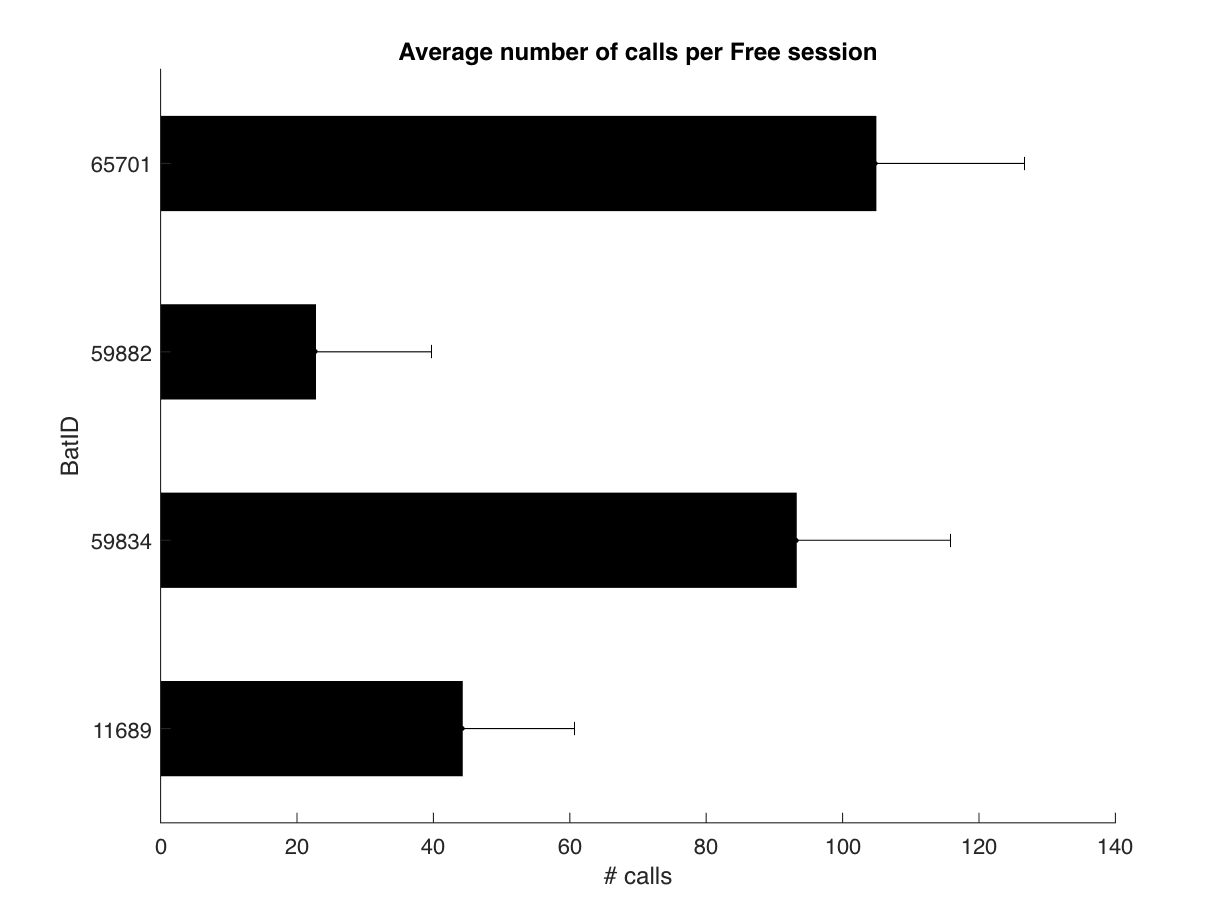

figure()
BAR2 = bar(mean(CountByIDAndDateFree(ImpInd,:),2,'omitnan'));
BAR2.Parent.YTick = 1:length(ImpInd);
BAR2.Parent.YTickLabel = UBatIDs(ImpInd);
BAR2.Horizontal = 'on';
BAR2.FaceColor = 'k';
BAR2.EdgeColor = 'k';
BAR2.BarWidth = 0.5;
ylim([0.5 4.5])
hold on
errorbar(mean(CountByIDAndDateFree(ImpInd,:),2,'omitnan'),1:length(ImpInd), 2*std(CountByIDAndDateFree(ImpInd,:),[],2,'omitnan')./sum(~isnan(CountByIDAndDateFree(ImpInd,:)),2).^0.5,'horizontal', 'k.')
hold off
title('Average number of calls per Free session')
ylabel('BatID')
xlabel('# calls')
box off

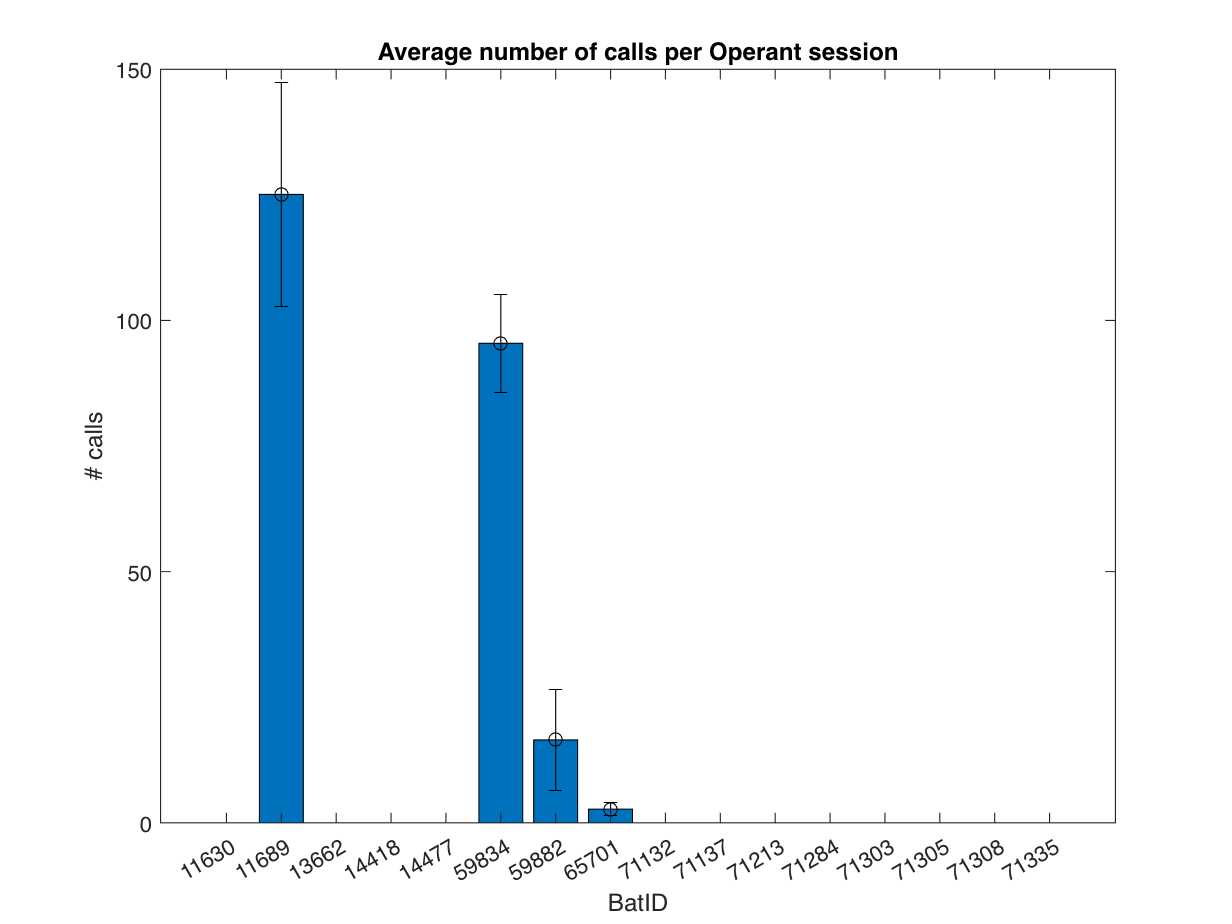

figure()
BAR2 = bar(nanmean(CountByIDAndDateOperant,2));
BAR2.Parent.XTick = 1:length(unique(BatIDs));
BAR2.Parent.XTickLabel = unique(BatIDs);
hold on
errorbar(1:length(unique(BatIDs)),mean(CountByIDAndDateOperant,2,'omitnan'), 2*std(CountByIDAndDateOperant,[],2,'omitnan')./sum(~isnan(CountByIDAndDateFree),2).^0.5, 'ko')
hold off
title('Average number of calls per Operant session')
xlabel('BatID')
ylabel('# calls')

% Focusing on Implanted bats
UBatIDs = unique(BatIDs);
ImpInd = [2 6:8];
fprintf(1,'These are the implanted bats:\n')

These are the implanted bats:


UBatIDs(ImpInd)

ans = 4×1 cell array
    {'11689'}
    {'59834'}
    {'59882'}
    {'65701'}


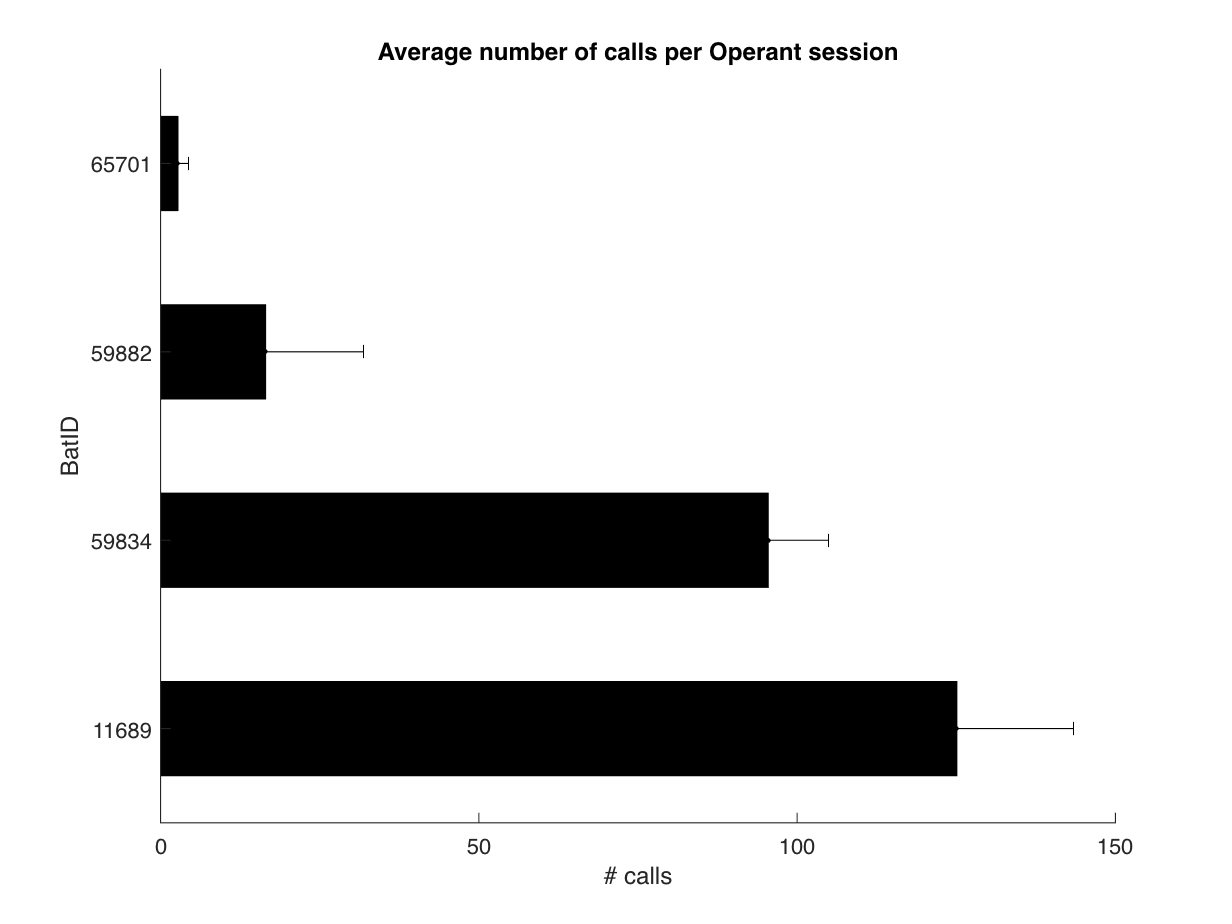

figure()
BAR2 = bar(mean(CountByIDAndDateOperant(ImpInd,:),2,'omitnan'));
BAR2.Parent.YTick = 1:length(ImpInd);
BAR2.Parent.YTickLabel = UBatIDs(ImpInd);
BAR2.Horizontal = 'on';
BAR2.FaceColor = 'k';
BAR2.EdgeColor = 'k';
BAR2.BarWidth = 0.5;
ylim([0.5 4.5])
hold on
errorbar(mean(CountByIDAndDateOperant(ImpInd,:),2,'omitnan'),1:length(ImpInd), 2*std(CountByIDAndDateOperant(ImpInd,:),[],2,'omitnan')./sum(~isnan(CountByIDAndDateOperant(ImpInd,:)),2).^0.5,'horizontal', 'k.')
hold off
title('Average number of calls per Operant session')
ylabel('BatID')
xlabel('# calls')
box off

figure();
BAR = bar(DurationByID/10^3);
BAR(1).Parent.XTick = 1:length(unique(BatIDs));
BAR(1).Parent.XTickLabel = unique(BatIDs);
title(sprintf('Total Time calling over %d free sessions and %d operant sessions', FreeSessionNb, OpSessionNb))
legend('Operant', 'Free','Location', 'best')
xlabel('BatID')
ylabel('Time calling (s)')

figure()
BAR2 = bar(nanmean(DurationByIDAndDateFree,2)/10^3);
BAR2.Parent.XTick = 1:length(unique(BatIDs));
BAR2.Parent.XTickLabel = unique(BatIDs);
hold on
errorbar(1:length(unique(BatIDs)),mean(DurationByIDAndDateFree/10^3,2,'omitnan'), 2*std(DurationByIDAndDateFree/10^3,[],2,'omitnan')./sum(~isnan(DurationByIDAndDateFree/10^3),2).^0.5, 'ko')
hold off
title('Average Time calling per Free session')
xlabel('BatID')
ylabel('Time calling (s)')

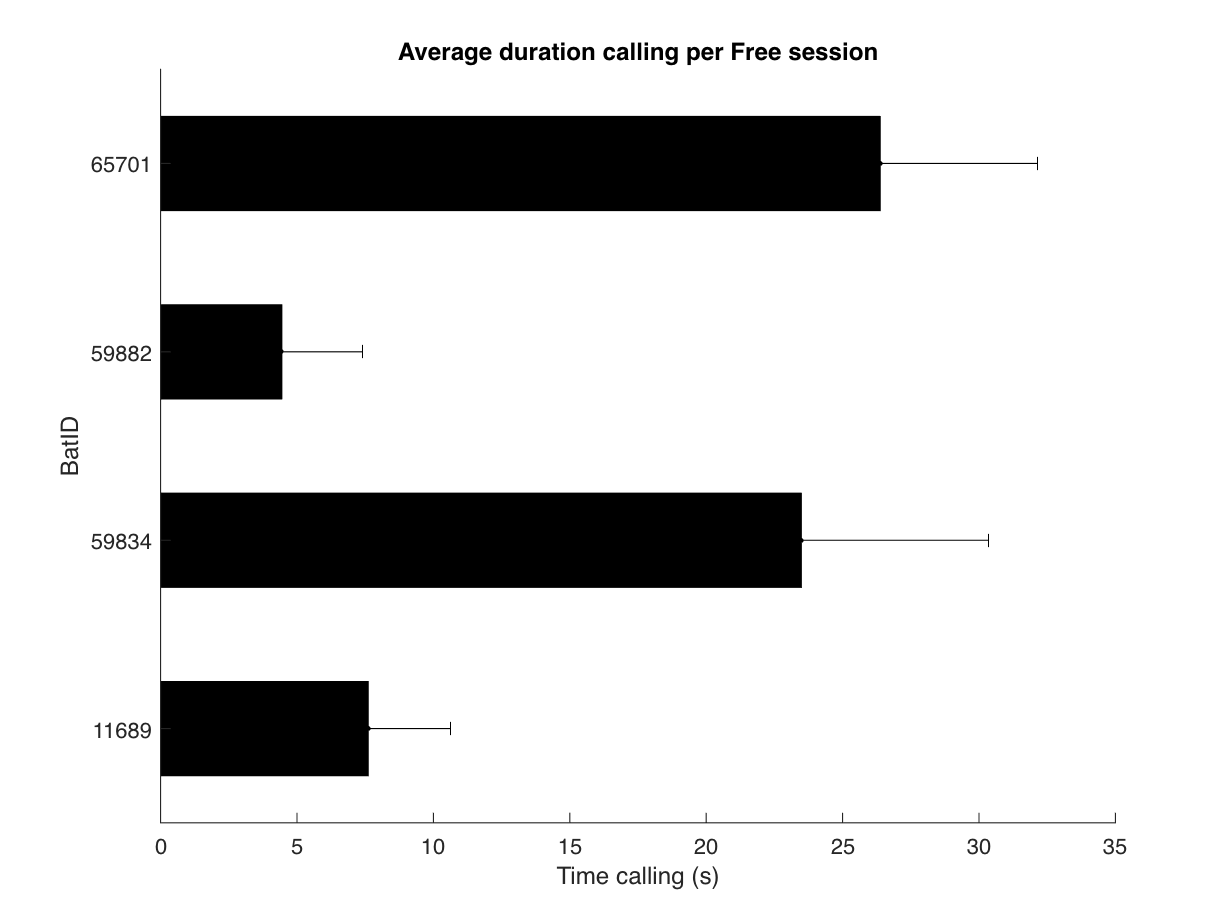

% Focusing on Implanted bats
figure()
BAR2 = bar(mean(DurationByIDAndDateFree(ImpInd,:)/10^3,2,'omitnan'));
BAR2.Parent.YTick = 1:length(ImpInd);
BAR2.Parent.YTickLabel = UBatIDs(ImpInd);
BAR2.Horizontal = 'on';
BAR2.FaceColor = 'k';
BAR2.EdgeColor = 'k';
BAR2.BarWidth = 0.5;
ylim([0.5 4.5])
hold on
errorbar(mean(DurationByIDAndDateFree(ImpInd,:)/10^3,2,'omitnan'),1:length(ImpInd), 2*std(DurationByIDAndDateFree(ImpInd,:)/10^3,[],2,'omitnan')./sum(~isnan(DurationByIDAndDateFree(ImpInd,:)),2).^0.5,'horizontal', 'k.')
hold off
title('Average duration calling per Free session')
ylabel('BatID')
xlabel('Time calling (s)')
box off

figure()
BAR2 = bar(nanmean(DurationByIDAndDateOperant,2)/10^3);
BAR2.Parent.XTick = 1:length(unique(BatIDs));
BAR2.Parent.XTickLabel = unique(BatIDs);
hold on
errorbar(1:length(unique(BatIDs)),mean(DurationByIDAndDateOperant/10^3,2,'omitnan'), 2*std(DurationByIDAndDateOperant/10^3,[],2,'omitnan')./sum(~isnan(DurationByIDAndDateOperant/10^3),2).^0.5, 'ko')
hold off
title('Average time calling per Operant session')
xlabel('BatID')
ylabel('Time calling (s)')

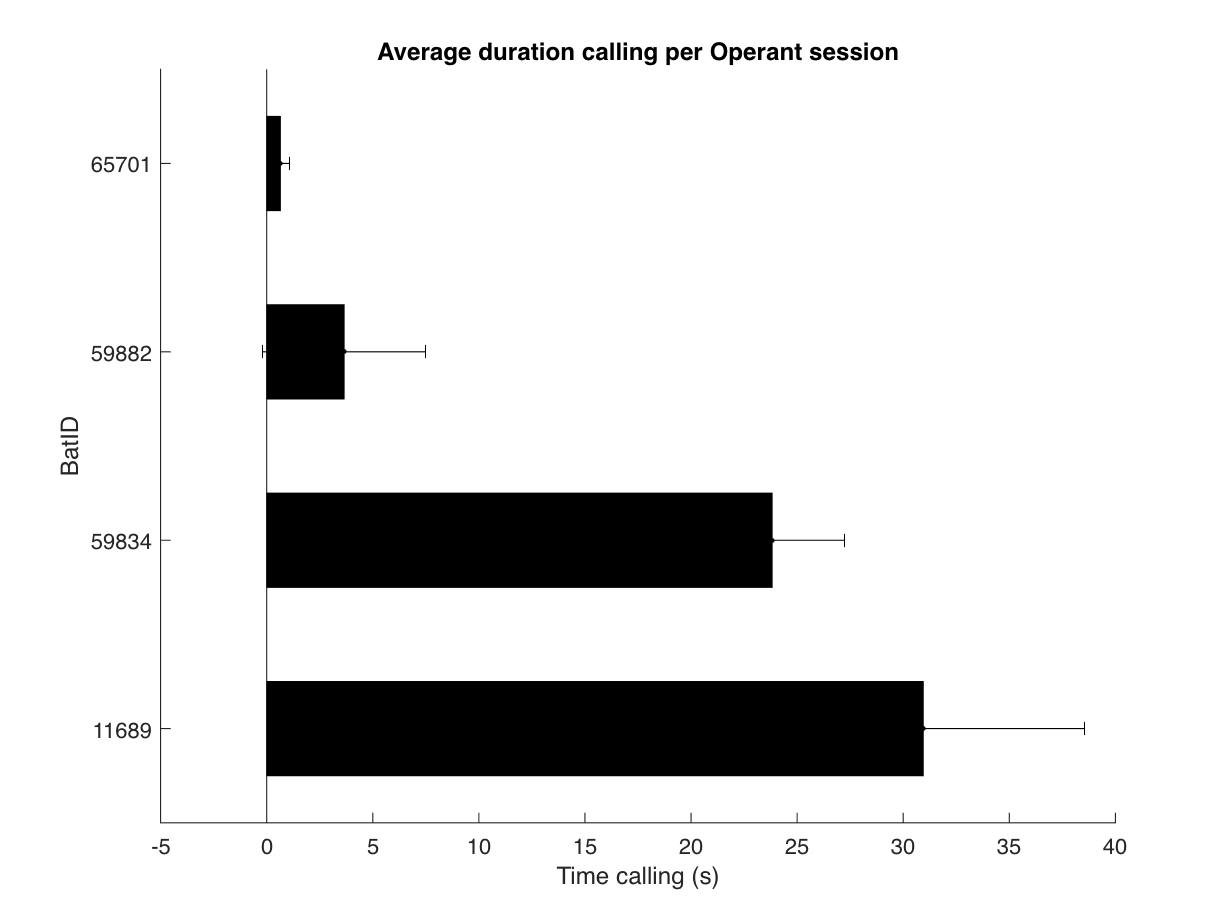

% Focusing on Implanted bats
figure()
BAR2 = bar(mean(DurationByIDAndDateOperant(ImpInd,:)/10^3,2,'omitnan'));
BAR2.Parent.YTick = 1:length(ImpInd);
BAR2.Parent.YTickLabel = UBatIDs(ImpInd);
BAR2.Horizontal = 'on';
BAR2.FaceColor = 'k';
BAR2.EdgeColor = 'k';
BAR2.BarWidth = 0.5;
ylim([0.5 4.5])
hold on
errorbar(mean(DurationByIDAndDateOperant(ImpInd,:)/10^3,2,'omitnan'),1:length(ImpInd), 2*std(DurationByIDAndDateOperant(ImpInd,:)/10^3,[],2,'omitnan')./sum(~isnan(DurationByIDAndDateOperant(ImpInd,:)),2).^0.5,'horizontal', 'k.')
hold off
title('Average duration calling per Operant session')
ylabel('BatID')
xlabel('Time calling (s)')
box off

figure()
FIG3 = subplot(2,1,1);
BAR3=bar(CountByIDAndDateFree');
FIG3.XTick = 1:length(unique(Dates));
FIG3.XTickLabel = unique(Dates);
title('# calls Free sessions')
xlabel('Dates')
ylabel('# calls')
legend(unique(BatIDs));

FIG4 = subplot(2,1,2);
BAR4=bar(CountByIDAndDateOperant');
FIG4.XTick = 1:length(unique(Dates));
FIG4.XTickLabel = unique(Dates);
title('# calls Operant sessions')
xlabel('Dates')
ylabel('# calls')
legend(unique(BatIDs));

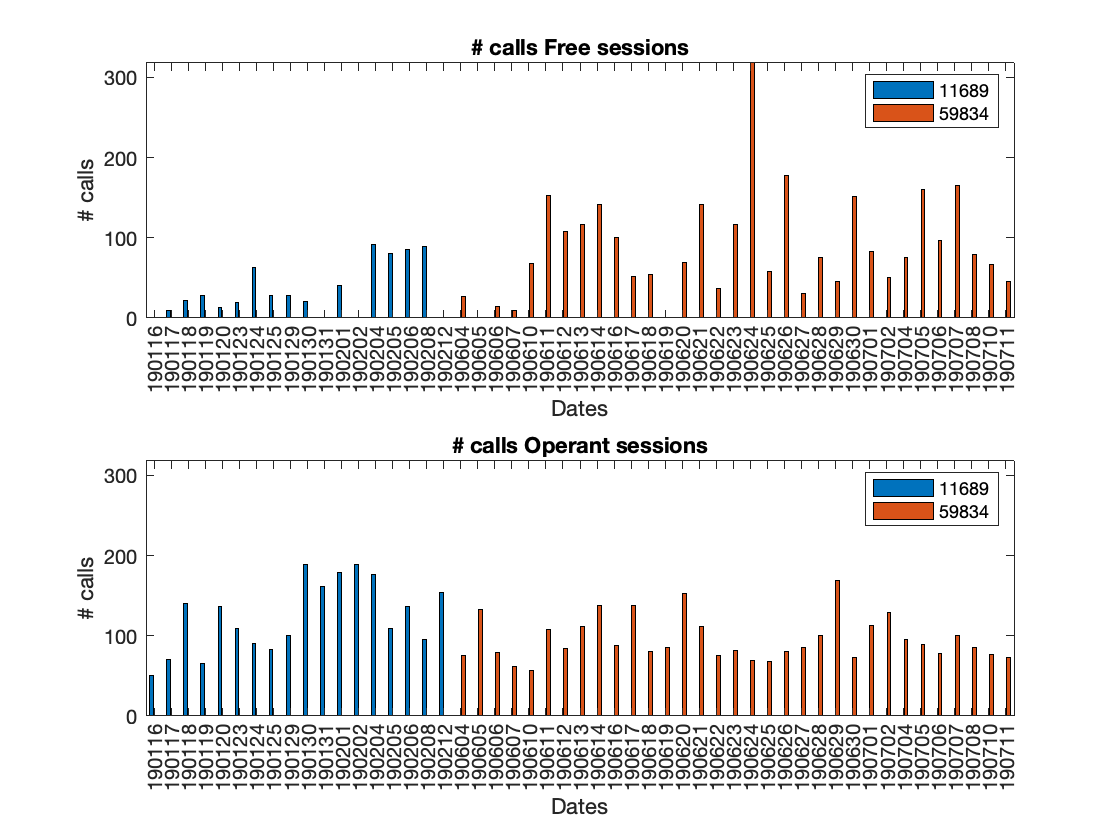

figure()
FIG3 = subplot(2,1,1);
BAR3=bar(CountByIDAndDateFree([2 6],:)');
FIG3.XTick = 1:length(unique(Dates));
FIG3.XTickLabel = unique(Dates);
title('# calls Free sessions')
xlabel('Dates')
ylabel('# calls')
legend(num2str(BatU([2, 6])));
Ylim1 = get(gca, 'YLim');

FIG4 = subplot(2,1,2);
BAR4=bar(CountByIDAndDateOperant([2 6],:)');
FIG4.XTick = 1:length(unique(Dates));
FIG4.XTickLabel = unique(Dates);
title('# calls Operant sessions')
xlabel('Dates')
ylabel('# calls')
legend(num2str(BatU([2, 6])));
ylim(Ylim1)

figure()
FIG3 = subplot(2,1,1);
BAR3=bar(DurationByIDAndDateFree([2 6],:)'./10^3);
FIG3.XTick = 1:length(unique(Dates));
FIG3.XTickLabel = unique(Dates);
title('Time Calling Free sessions')
xlabel('Dates')
ylabel('Time Calling (s)')
legend(num2str(BatU([2, 6])));
Ylim1 = get(gca, 'YLim');

FIG4 = subplot(2,1,2);
BAR4=bar(DurationByIDAndDateOperant([2 6],:)'./10^3);
FIG4.XTick = 1:length(unique(Dates));
FIG4.XTickLabel = unique(Dates);
title('Time Calling Operant sessions')
xlabel('Dates')
ylabel('Time Calling (s)')
legend(num2str(BatU([2, 6])));
ylim(Ylim1)

figure()
FIG5 = subplot(2,1,1);
bar(CuratedDateSeqFree', 'stacked')
FIG5.XTick = 1:length(unique(Dates));
FIG5.XTickLabel = unique(Dates);
title('# curated sequences Free session')
xlabel('Dates')
ylabel('# sequences')
legend({'only noise' 'calls'})

FIG6 = subplot(2,1,2);
bar(CuratedDateSeqOperant', 'stacked')
FIG6.XTick = 1:length(unique(Dates));
FIG6.XTickLabel = unique(Dates);
title('# curated sequences Operant session')
xlabel('Dates')
ylabel('# sequences')
legend({'only noise' 'calls'})

## Calculate inter call intervals per bat and per day

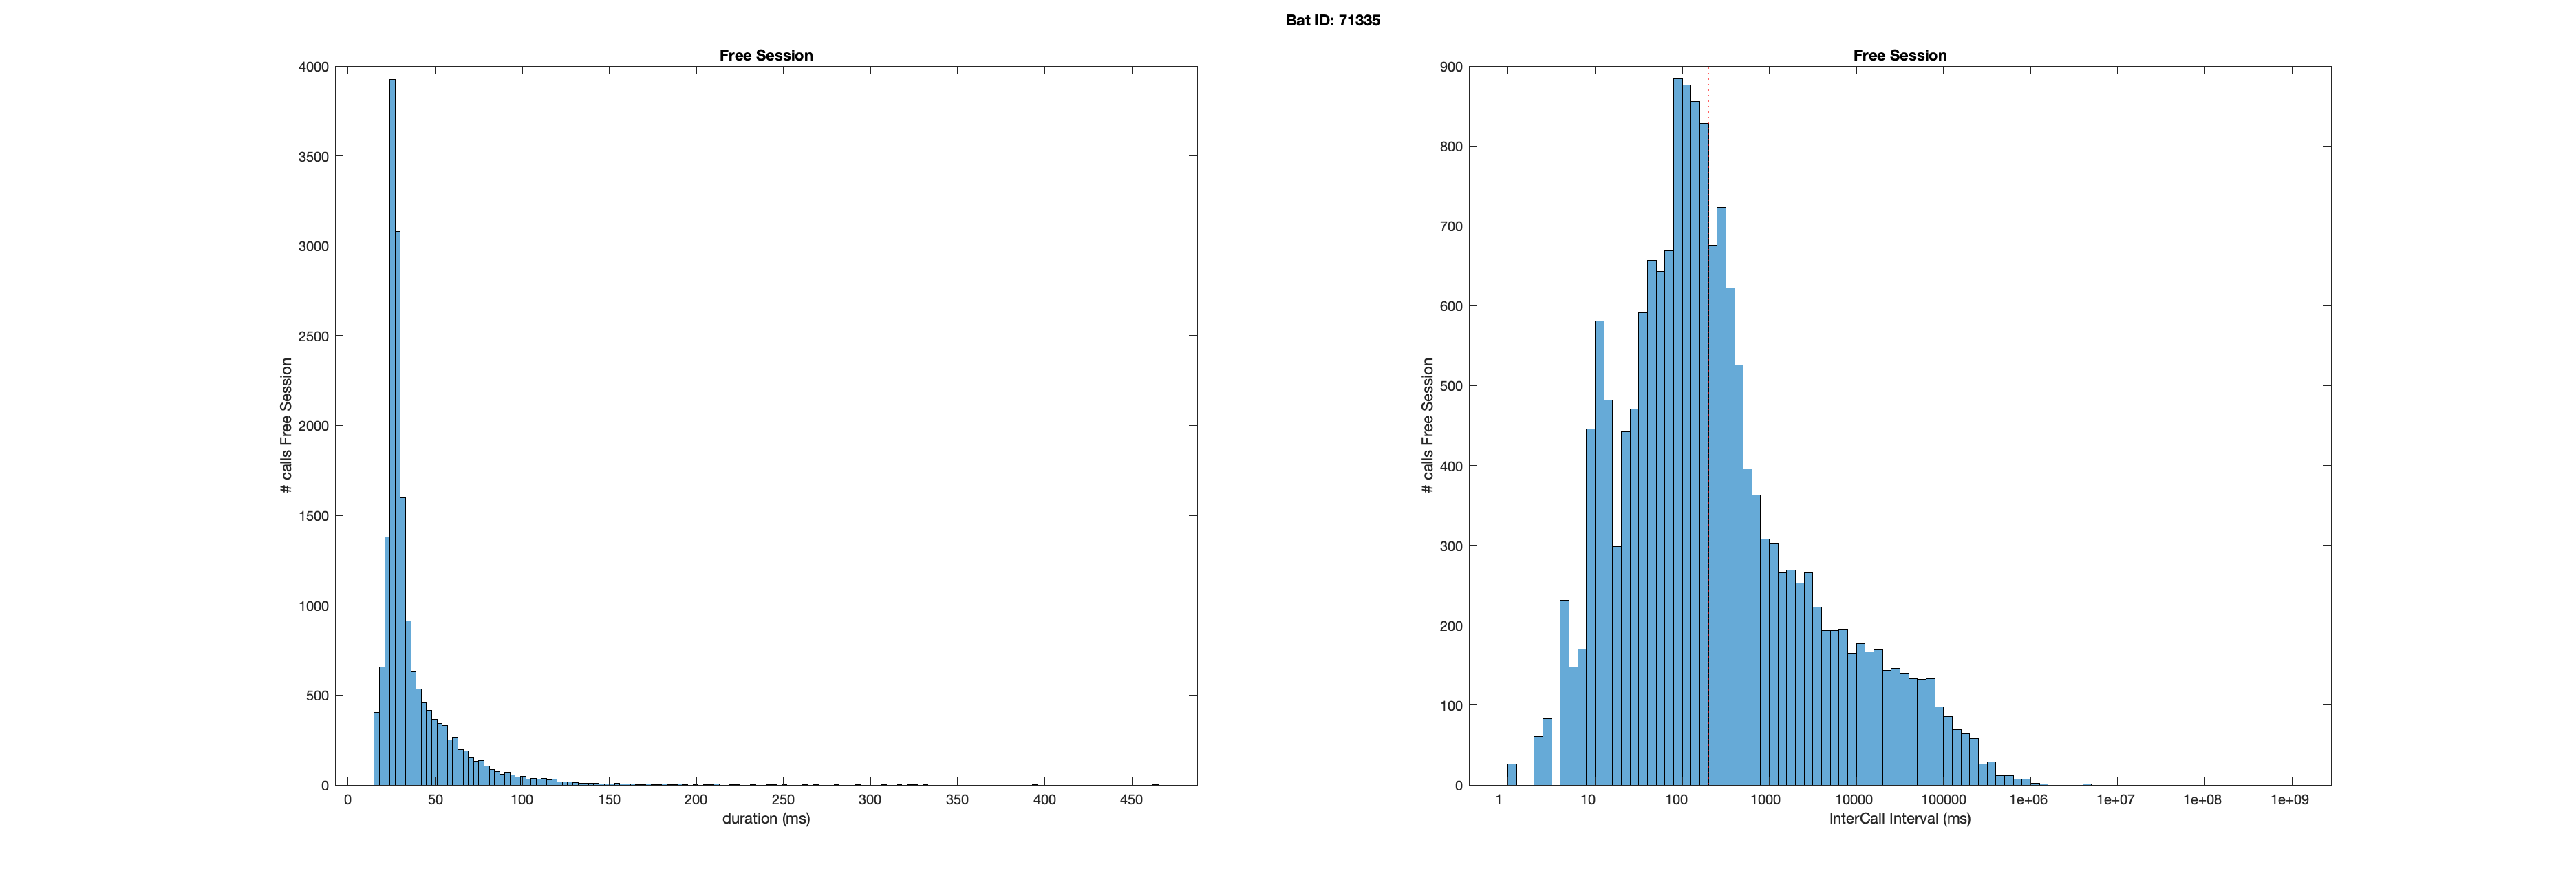

BatU = unique(CallOnSetOffsetBat);
DateU = unique(CallOnSetOffsetDate);
ICOI_Free_intra=cell(1,length(BatU)); % Inter call onset intervals intra individuals, all bats
ICOI_Free_inter=cell(1,length(DateU)); % Inter call onset intervals inter individuals, all bats


for BatI = 1:length(BatU)
    BatI_logical = CallOnSetOffsetBat == BatU(BatI);
    DateBatI = unique(CallOnSetOffsetDate(BatI_logical));
    ICOI_Free_intra{BatI} = cell(1,length(DateBatI));
    if sum(CallOnSetOffsetSessionID(CallOnSetOffsetBat == BatU(BatI))) % This bat was also calling during operant tests
        ICI_Free = cell(1,length(DateBatI));
        ICI_Operant = cell(1,length(DateBatI));
        ICOI_Free = cell(1,length(DateBatI));
        ICOI_Operant = cell(1,length(DateBatI));
        CallDuration_Free = cell(1,length(DateBatI));
        CallDuration_Operant = cell(1,length(DateBatI));
    else
        ICI_Free = cell(1,length(DateBatI));
        ICI_Operant = [];
        ICOI_Free = cell(1,length(DateBatI));
        ICOI_Operant = [];
        CallDuration_Free = cell(1,length(DateBatI));
        CallDuration_Operant = [];
    end
    for dd=1:length(DateBatI)
        BatIDateI = find(BatI_logical .* (CallOnSetOffsetDate==DateBatI(dd)));
        if isempty(ICI_Operant) % Only free session data
            Onset_free_local = CallOnSetOffset(BatIDateI,1)';
            Offset_free_local = CallOnSetOffset(BatIDateI,2)';
            CallDuration_Free{dd} = Offset_free_local - Onset_free_local;
            [~,SortOn] = sort(Onset_free_local);
            if any(diff(SortOn)~=1)
                [~,SortOff] = sort(Offset_free_local);
                if any(SortOn~=SortOff)
                    warning('Issues with calls not ordered properly in time!!\n')
                    Onset_free_local = Onset_free_local(SortOn);
                    Offset_free_local = Offset_free_local(SortOn);
%                     keyboard
                else
                   Onset_free_local = Onset_free_local(SortOn);
                   Offset_free_local = Offset_free_local(SortOff);
                end
            end
            ICI_Free{dd} = Onset_free_local(2:end) - Offset_free_local(1:end-1);
            ICOI_Free{dd} = diff(Onset_free_local);
        else
            BatIDateIFree = intersect(BatIDateI, find(~CallOnSetOffsetSessionID));
            Onset_free_local = CallOnSetOffset(BatIDateIFree,1)';
            Offset_free_local = CallOnSetOffset(BatIDateIFree,2)';
            CallDuration_Free{dd} = Offset_free_local - Onset_free_local;
            [~,SortOn] = sort(Onset_free_local);
            if any(diff(SortOn)~=1)
                [~,SortOff] = sort(Offset_free_local);
                if any(SortOn~=SortOff)
                    warning('Issues with calls not ordered properly in time!!\n')
                    Onset_free_local = Onset_free_local(SortOn);
                    Offset_free_local = Offset_free_local(SortOn);
%                     keyboard
                else
                   Onset_free_local = Onset_free_local(SortOn);
                   Offset_free_local = Offset_free_local(SortOff);
                end
            end
            ICI_Free{dd} = Onset_free_local(2:end) - Offset_free_local(1:end-1);
            ICOI_Free{dd} = diff(Onset_free_local);
            
            BatIDateIOp = intersect(BatIDateI, find(CallOnSetOffsetSessionID));
            Onset_Op_local = CallOnSetOffset(BatIDateIOp,1)';
            Offset_Op_local = CallOnSetOffset(BatIDateIOp,2)';
            CallDuration_Operant{dd} = Offset_Op_local - Onset_Op_local;
            [~,SortOn] = sort(Onset_Op_local);
            if any(diff(SortOn)~=1)
                [~,SortOff] = sort(Offset_Op_local);
                if any(SortOn~=SortOff)
                    warning('Issues with calls not ordered properly in time!!\n')
                    Onset_Op_local = Onset_Op_local(SortOn);
                    Offset_Op_local = Offset_Op_local(SortOn);
%                     keyboard
                else
                   Onset_Op_local = Onset_Op_local(SortOn);
                   Offset_Op_local = Offset_Op_local(SortOff);
                end
            end
            ICI_Operant{dd} = Onset_Op_local(2:end) - Offset_Op_local(1:end-1);
            ICOI_Operant{dd} = diff(Onset_Op_local);
        end
        ICOI_Free_intra{BatI}{dd} = diff(Onset_free_local);
        if any(ICOI_Free_intra{BatI}{dd}<0)
            keyboard
        end
    end
    
    CallDuration_Free = [CallDuration_Free{:}]';
    ICI_Free = [ICI_Free{:}]';
    ICI_Free = ICI_Free(ICI_Free>=0);
    ICOI_Free = [ICOI_Free{:}]';
    ICOI_Free = ICOI_Free(ICOI_Free>=0);
    ICOI_Free_intra{BatI} = [ICOI_Free_intra{BatI}{:}];
    if ~isempty(ICI_Operant)
        CallDuration_Operant = [CallDuration_Operant{:}]';
        ICI_Operant = [ICI_Operant{:}]';
        ICI_Operant = ICI_Operant(ICI_Operant>=0);
        ICOI_Operant = [ICOI_Operant{:}]';
        ICOI_Operant = ICOI_Operant(ICOI_Operant>=0);
    end
    F1=figure(1);
    clf(F1)
    set(F1,'Visible','on')
    if isempty(ICI_Operant) % Only free session data
        subplot(1,2,1)
        histogram(CallDuration_Free)
        ylabel('# calls Free Session')
        xlabel('duration (ms)')
        title('Free Session')
        
        subplot(1,2,2)
        histogram(ICI_Free)
        H=histogram(log10(ICI_Free));
        H.BinEdges = 0:0.1:9;
        H.Parent.XTick = 0:9;
        H.Parent.XTickLabel = power(10, H.Parent.XTick);
        ylabel('# calls Free Session')
        xlabel('InterCall Interval (ms)')
        hold on
        vline(log10(200), ':r')
        title('Free Session')
    else
        subplot(2,4,1)
        histogram(CallDuration_Free)
        ylabel('# calls Free Session')
        xlabel('duration (ms)')
        title('Free Session')
        
        subplot(2,4,2)
%         histogram(ICI_Free)
        H=histogram(log10(ICI_Free));
        H.BinEdges = 0:0.1:9;
        H.Parent.XTick = 0:9;
        H.Parent.XTickLabel = power(10, H.Parent.XTick);
        ylabel('# calls Free Session')
        xlabel('InterCall Interval (ms)')
        hold on
        vline(log10(200), ':r')
        title('Free Session')
        
        subplot(2,4,3)
        histogram(CallDuration_Operant)
        ylabel('# calls Operant Session')
        xlabel('duration (ms)')
        title('Operant Session')
        
        subplot(2,4,4)
%         histogram(ICI_Operant)
        H=histogram(log10(ICI_Operant));
        H.BinEdges = 0:0.1:9;
        H.Parent.XTick = 0:9;
        H.Parent.XTickLabel = power(10, H.Parent.XTick);
        ylabel('# calls Operant Session')
        xlabel('InterCall Interval (ms)')
        hold on
        vline(log10(200), ':r')
        title('Operant Session')
        
        subplot(2,4,5)
        H=histogram(log10(ICOI_Free), 'FaceColor','k', 'Normalization', 'cdf');
        H.BinEdges = 0:0.1:9;
        H.Parent.XTick = 0:9;
        H.Parent.XTickLabel = power(10, H.Parent.XTick);
        ylabel('# calls Free Session')
        xlabel('InterCall Onset Interval (ms)')
        title('Free Session')
        
        subplot(2,4,6)
        H=histogram(log10(ICOI_Operant), 'FaceColor', 'k', 'Normalization', 'probability');
        H.BinEdges = 0:0.1:9;
        H.Parent.XTick = 0:9;
        H.Parent.XTickLabel = power(10, H.Parent.XTick);
        ylabel('# calls Operant Session')
        xlabel('InterCall Onset Interval (ms)')
        title('Operant Session')
        
        subplot(2,4,7)
        H=histogram2(log10(ICOI_Free(1:end-1)), log10(ICOI_Free(2:end)), 0:0.1:9, 0:0.1:9, 'DisplayStyle','tile', 'Normalization', 'probability');
        H.Parent.XTick = 0:9;
        H.Parent.XTickLabel = power(10, H.Parent.XTick);
        H.Parent.YTick = 0:9;
        H.Parent.YTickLabel = power(10, H.Parent.YTick);
        xlabel('InterCall Onset Interval before a given call (ms)')
        ylabel('InterCall Onset Interval after a given call (ms)')
        CBar = colorbar;
        ylabel(CBar, 'probability')
        title('Free Session')
        grid off
        box off
        
        subplot(2,4,8)
        H=histogram2(log10(ICOI_Operant(1:end-1)), log10(ICOI_Operant(2:end)), 0:0.1:9, 0:0.1:9, 'DisplayStyle','tile', 'Normalization', 'probability');
        H.Parent.XTick = 0:9;
        H.Parent.XTickLabel = power(10, H.Parent.XTick);
        H.Parent.YTick = 0:9;
        H.Parent.YTickLabel = power(10, H.Parent.YTick);
        xlabel('InterCall Onset Interval before a given call (ms)')
        ylabel('InterCall Onset Interval after a given call (ms)')
        CBar = colorbar;
        ylabel(CBar, 'probability')
        title('Operant Session')
        grid off
        box off
    end
    suplabel(sprintf('Bat ID: %d', BatU(BatI)) ,'t');
    keyboard
end


ICOI_Free_intra = [ICOI_Free_intra{:}]';

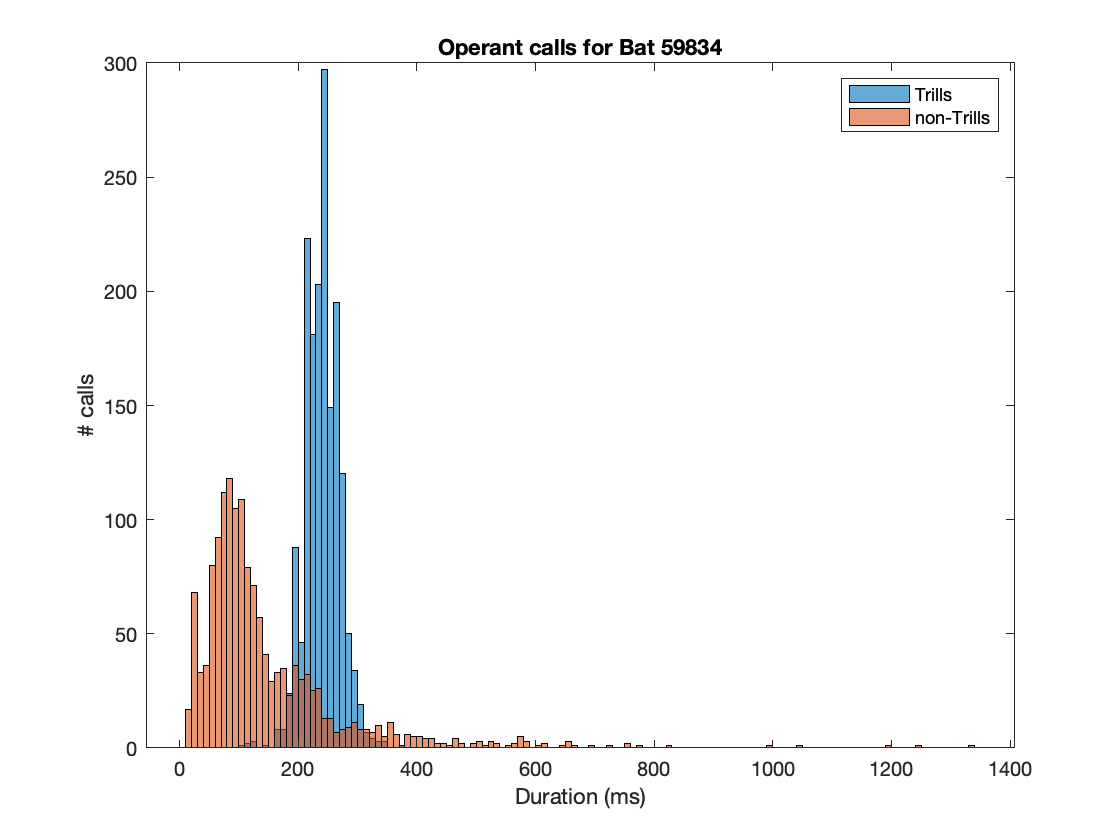

% Look into the vocalization durations of Cooper and Hodor in Operant for
% Trills and non-trills
figure()
histogram(Duration_ms(logical(Trills01.*SessionID.*(str2double(BatIDs)==59834))), 'BinWidth',10);
hold on
histogram(Duration_ms(logical((~Trills01).*SessionID.*(str2double(BatIDs)==59834))), 'BinWidth',10);
legend('Trills', 'non-Trills')
xlabel('Duration (ms)')
ylabel('# calls')
title('Operant calls for Bat 59834')

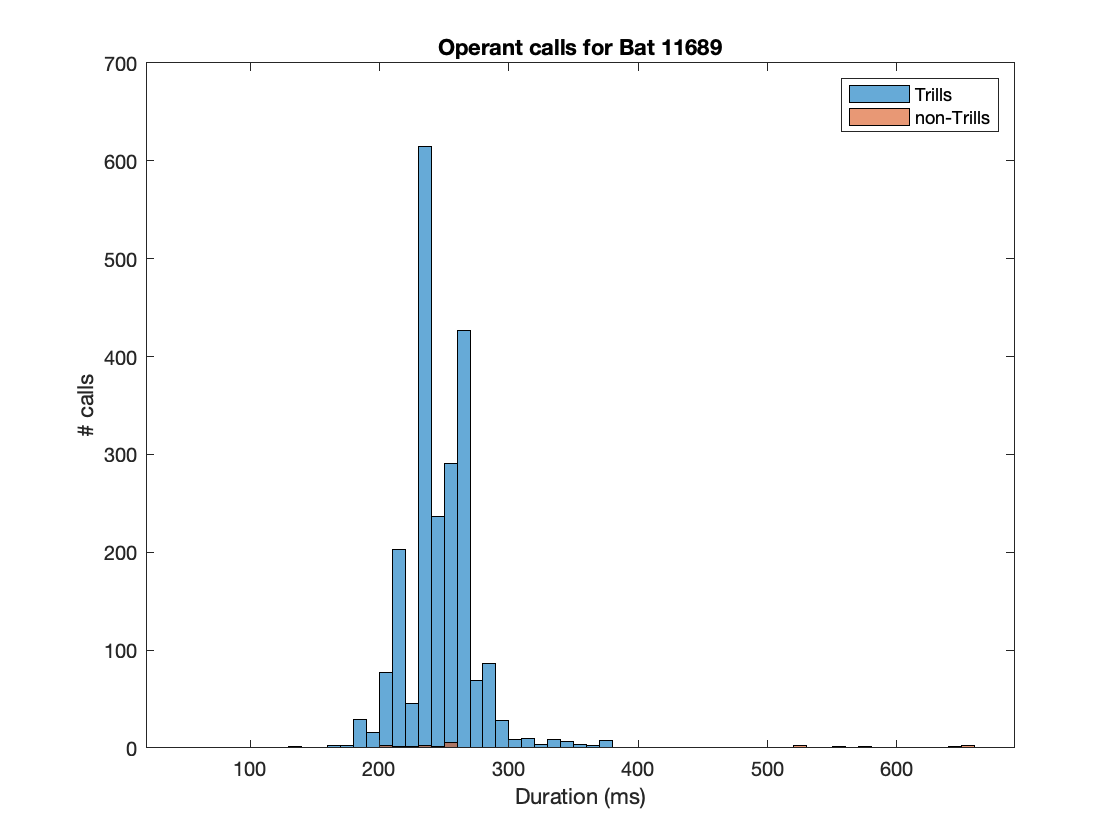

figure()
histogram(Duration_ms(logical(Trills01.*SessionID.*(str2double(BatIDs)==11689))), 'BinWidth',10);
hold on
histogram(Duration_ms(logical((~Trills01).*SessionID.*(str2double(BatIDs)==11689))), 'BinWidth',10);
legend('Trills', 'non-Trills')
xlabel('Duration (ms)')
ylabel('# calls')
title('Operant calls for Bat 11689')

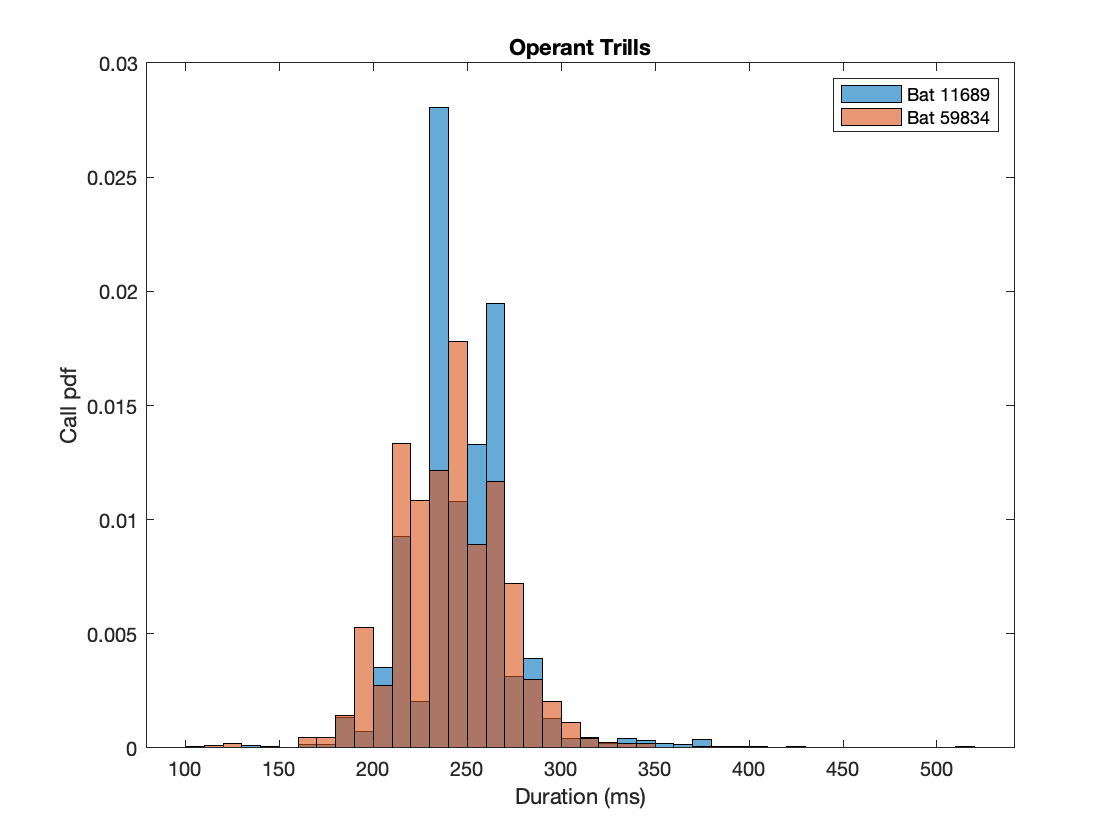


figure()
histogram(Duration_ms(logical(Trills01.*SessionID.*(str2double(BatIDs)==11689))), 'BinWidth',10,'Normalization', 'pdf');
hold on
histogram(Duration_ms(logical(Trills01.*SessionID.*(str2double(BatIDs)==59834))), 'BinWidth',10,'Normalization', 'pdf');
legend('Bat 11689', 'Bat 59834')
xlabel('Duration (ms)')
ylabel('Call pdf')
title('Operant Trills')

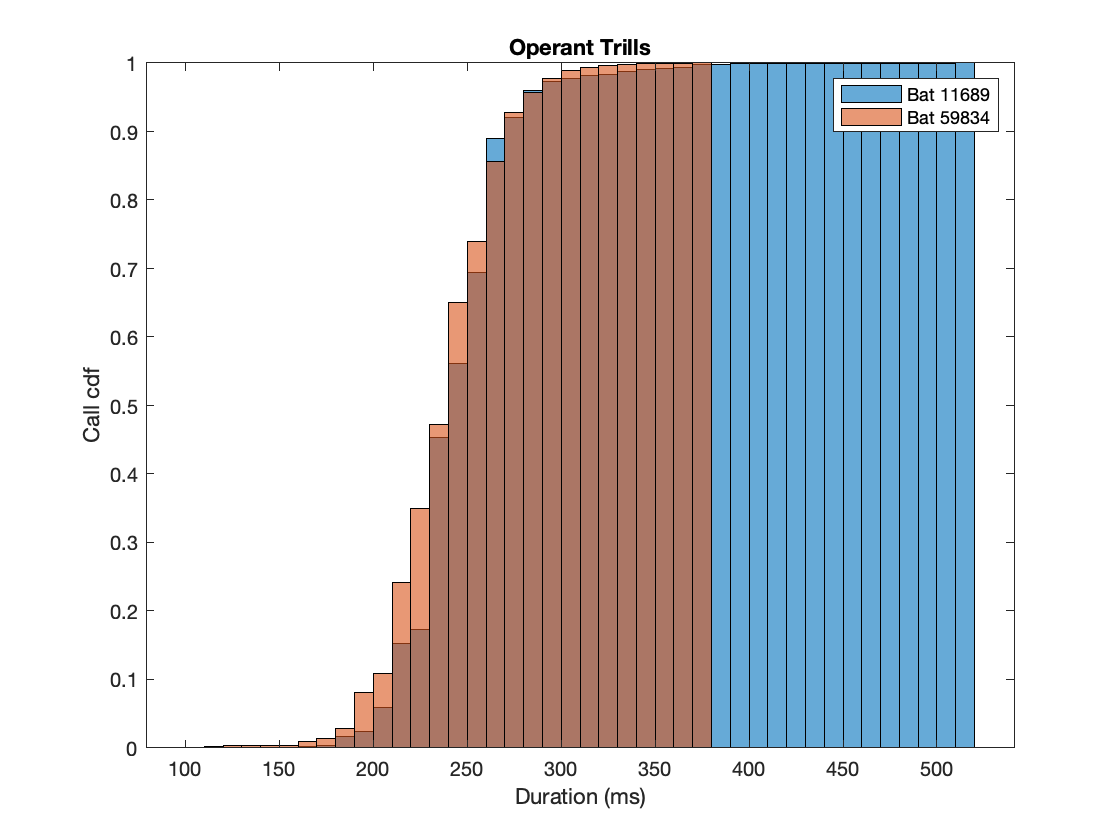


figure()
histogram(Duration_ms(logical(Trills01.*SessionID.*(str2double(BatIDs)==11689))), 'BinWidth',10,'Normalization', 'cdf');
hold on
histogram(Duration_ms(logical(Trills01.*SessionID.*(str2double(BatIDs)==59834))), 'BinWidth',10,'Normalization', 'cdf');
legend('Bat 11689', 'Bat 59834')
xlabel('Duration (ms)')
ylabel('Call cdf')
title('Operant Trills')

TrillSelect = logical(Trills01.*SessionID.*(str2double(BatIDs)==11689));
fprintf(1, 'Percentage of Trills duration below 300ms for 11689: %.2f%%/n',sum(Duration_ms(TrillSelect)<=300)/sum(TrillSelect)*100)

Percentage of Trills duration below 300ms for 11689: 97.40%/n

TrillSelect = logical(Trills01.*SessionID.*(str2double(BatIDs)==59834));
fprintf(1, 'Percentage of Trills duration below 300ms for 59834: %.2f%%/n',sum(Duration_ms(TrillSelect)<=300)/sum(TrillSelect)*100)

Percentage of Trills duration below 300ms for 59834: 97.96%/n

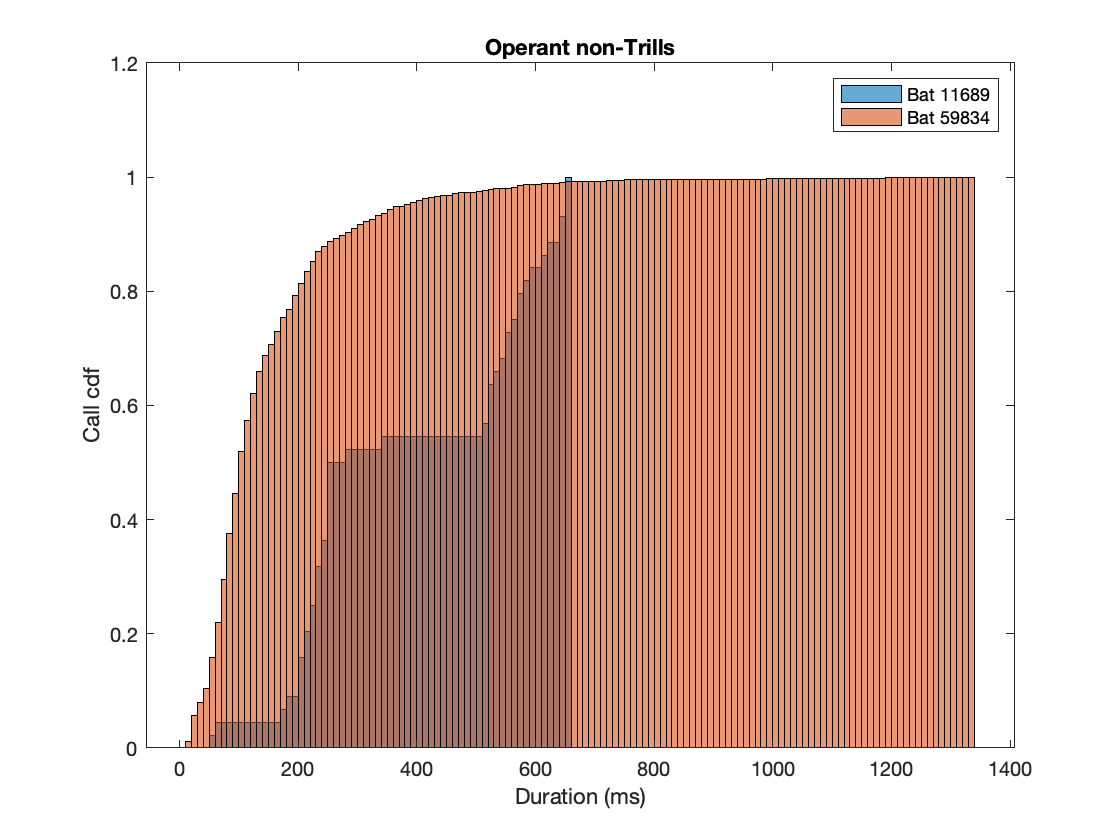


figure()
histogram(Duration_ms(logical((~Trills01).*SessionID.*(str2double(BatIDs)==11689))), 'BinWidth',10,'Normalization', 'cdf');
hold on
histogram(Duration_ms(logical((~Trills01).*SessionID.*(str2double(BatIDs)==59834))), 'BinWidth',10,'Normalization', 'cdf');
legend('Bat 11689', 'Bat 59834')
xlabel('Duration (ms)')
ylabel('Call cdf')
title('Operant non-Trills')

TrillSelect = logical((~Trills01).*SessionID.*(str2double(BatIDs)==11689));
fprintf(1, 'Percentage of non-Trills duration below 300ms for 11689: %.2f%%/n',sum(Duration_ms(TrillSelect)<=300)/sum(TrillSelect)*100)

Percentage of non-Trills duration below 300ms for 11689: 52.27%/n

TrillSelect = logical((~Trills01).*SessionID.*(str2double(BatIDs)==59834));
fprintf(1, 'Percentage of non-Trills duration below 300ms for 59834: %.2f%%/n',sum(Duration_ms(TrillSelect)<=300)/sum(TrillSelect)*100)

Percentage of non-Trills duration below 300ms for 59834: 91.15%/n

% Now get the intercall onsets intervals accross bats
for dd=1:length(DateU)
    DateI_logical = CallOnSetOffsetDate == DateU(dd);
    DateIFree = intersect(find(DateI_logical), find(~CallOnSetOffsetSessionID));
    Onset_free_local = CallOnSetOffset(DateIFree,1)';
    [Onset_free_local_sorted,SortOn] = sort(Onset_free_local);
    BatID_local = CallOnSetOffsetBat(DateIFree);
    if any(diff(SortOn)~=1)
        fprintf(1,'Reordering calls for %d', DateU(dd))
        BatID_local = BatID_local(SortOn);
    end
    % identify intercalls intervals accross bats
    ICOI = diff(Onset_free_local_sorted);
    if any(ICOI<0)
        keyboard
    end
    InterBats = find(diff(BatID_local));
    ICOI_Free_inter{dd} = ICOI(InterBats); 
end

Reordering calls for 190119Reordering calls for 190120Reordering calls for 190123Reordering calls for 190124Reordering calls for 190125Reordering calls for 190129Reordering calls for 190130Reordering calls for 190201Reordering calls for 190204Reordering calls for 190205Reordering calls for 190206Reordering calls for 190208Reordering calls for 190604Reordering calls for 190607Reordering calls for 190610Reordering calls for 190611Reordering calls for 190612Reordering calls for 190613Reordering calls for 190614Reordering calls for 190616Reordering calls for 190617Reordering calls for 190618Reordering calls for 190620Reordering calls for 190621Reordering calls for 190622Reordering calls for 190623Reordering calls for 190624Reordering calls for 190625Reordering calls for 190626Reordering calls for 190627Reordering calls for 190628Reordering calls for 190629Reordering calls for 190630Reordering calls for 190701Reordering calls for 190702Reordering calls for 190704Reordering calls for 190705R


ICOI_Free_inter = [ICOI_Free_inter{:}]';


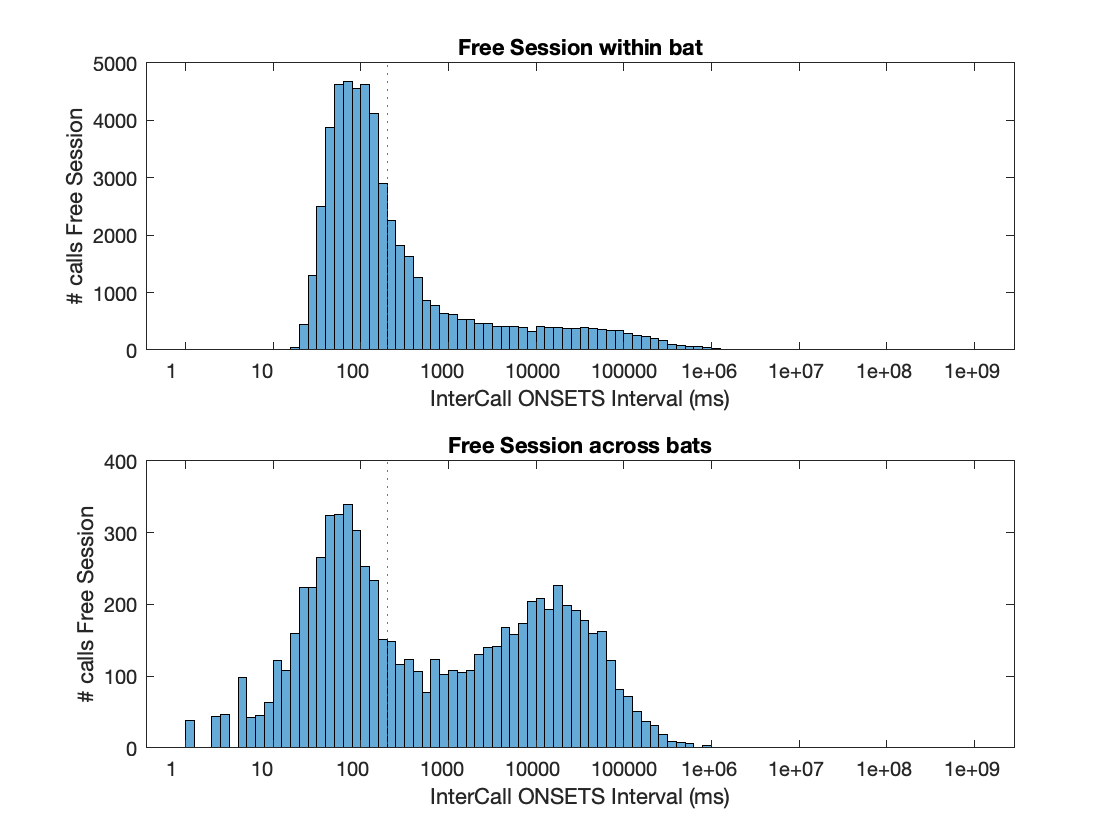

% Plot the distribution of intercall onset intervals intra and interbats
% LOG10 TIME SCALE
figure()
subplot(2,1,1)
% H=histogram(ICOI_Free_intra)
H=histogram(log10(ICOI_Free_intra));
H.BinEdges = 0:0.1:9;
H.Parent.XTick = 0:9;
H.Parent.XTickLabel = power(10, H.Parent.XTick);
ylabel('# calls Free Session')
xlabel('InterCall ONSETS Interval (ms)')
hold on
vline(log10(200), ':r')
title('Free Session within bat')

subplot(2,1,2)
H=histogram(log10(ICOI_Free_inter));
H.BinEdges = 0:0.1:9;
H.Parent.XTick = 0:9;
H.Parent.XTickLabel = power(10, H.Parent.XTick);
ylabel('# calls Free Session')
xlabel('InterCall ONSETS Interval (ms)')
hold on
vline(log10(200), ':r')
title('Free Session across bats')

% Plot the distribution of intercall onset intervals intra and interbats
% LINEAR TIME SCALE on 1 second
figure()
subplot(2,1,1)
H=histogram(ICOI_Free_intra(ICOI_Free_intra<=1000), 50);
ylabel('# calls Free Session')
xlabel('InterCall ONSETS Interval (ms)')
hold on
vline(200, ':r')
title('Free Session within bat')

subplot(2,1,2)
H=histogram(ICOI_Free_inter(ICOI_Free_inter<=1000), 50);
ylabel('# calls Free Session')
xlabel('InterCall ONSETS Interval (ms)')
hold on
vline(200, ':r')
title('Free Session across bats')

## Acoustic landscape of calls in both sessions

figure(2)
scatter(Mean_Amp_piezo, Duration_ms,20,[0 0 0])
xlabel('Amplitude')
ylabel('Duration (ms)')
title(sprintf('n=%d',sum(~isnan(Mean_Amp_piezo))))

Short = Duration_ms<500;

figure(2)
scatter(Mean_Amp_piezo(Short), Duration_ms(Short),20,[0 0 0])
xlabel('Amplitude')
ylabel('Duration (ms)')
title(sprintf('n=%d',sum(~isnan(Mean_Amp_piezo(Short)))))

figure(1)

subplot(2,3,1)
scatter(Mean_Amp_piezo, Mean_Saliency_piezo,10,[0 0 0])
xlabel('Amplitude')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo))))

subplot(2,3,2)
scatter(Mean_Amp_piezo, Mean_SpecMean_piezo,10,[0 0 0])
xlabel('Amplitude')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo))))

subplot(2,3,3)
scatter(Mean_Amp_piezo, Mean_Fund_piezo,10,[0 0 0])
xlabel('Amplitude')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo))))

subplot(2,3,4)
scatter(Duration_ms(Short), Mean_Saliency_piezo(Short),10,[0 0 0])
xlabel('Duration (ms)')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo(Short)))))

subplot(2,3,5)
scatter(Duration_ms(Short), Mean_SpecMean_piezo(Short),10,[0 0 0])
xlabel('Duration (ms)')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo(Short)))))

subplot(2,3,6)
scatter(Duration_ms(Short), Mean_Fund_piezo(Short),10,[0 0 0])
xlabel('Duration (ms)')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo(Short)))))
suplabel('The soundscape of all calls')

## Relationship between pitch saliency and fundamental

figure(4)
scatter(Mean_Fund_piezo, Mean_Saliency_piezo,10,[0 0 0])
xlabel('Fundamental')
ylabel('Picth saliency')
title(sprintf('n=%d',min(sum(~isnan(Mean_Saliency_piezo)),sum(~isnan(Mean_Fund_piezo)))))

## How are trills dfferent from the rest?

figure(1)

subplot(2,3,1)
scatter(Mean_Amp_piezo, Mean_Saliency_piezo,10,Trills01*[0.4660, 0.6740, 0.1880])
xlabel('Amplitude')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo))))

subplot(2,3,2)
scatter(Mean_Amp_piezo, Mean_SpecMean_piezo,10,Trills01*[0.4660, 0.6740, 0.1880])
xlabel('Amplitude')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo))))

subplot(2,3,3)
scatter(Mean_Amp_piezo, Mean_Fund_piezo,10,Trills01*[0.4660, 0.6740, 0.1880])
xlabel('Amplitude')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo))))

subplot(2,3,4)
scatter(Duration_ms(Short), Mean_Saliency_piezo(Short),10,Trills01(Short)*[0.4660, 0.6740, 0.1880])
xlabel('Duration (ms)')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo(Short)))))

subplot(2,3,5)
scatter(Duration_ms(Short), Mean_SpecMean_piezo(Short),10,Trills01(Short)*[0.4660, 0.6740, 0.1880])
xlabel('Duration (ms)')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo(Short)))))

subplot(2,3,6)
scatter(Duration_ms(Short), Mean_Fund_piezo(Short),10,Trills01(Short)*[0.4660, 0.6740, 0.1880])
xlabel('Duration (ms)')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo(Short)))))
suplabel('Trills in this soundscape')

% Relationship between pitch saliency and fundamental
figure(4)
scatter(Mean_Fund_piezo, Mean_Saliency_piezo,10,Trills01*[0.4660, 0.6740, 0.1880])
xlabel('Fundamental')
ylabel('Picth saliency')
title(sprintf('n=%d',min(sum(~isnan(Mean_Saliency_piezo)),sum(~isnan(Mean_Fund_piezo)))))
suplabel('Trills in this soundscape')

## Are sessions covering a different sound landscape?

figure(1)
subplot(2,3,1)
scatter(Mean_Amp_piezo, Mean_Saliency_piezo,10,SessionID*[0, 0.4470, 0.7410] + (~SessionID)*[0.8500, 0.3250, 0.0980])
xlabel('Amplitude')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo))))

subplot(2,3,2)
scatter(Mean_Amp_piezo, Mean_SpecMean_piezo,10,SessionID*[0, 0.4470, 0.7410] + (~SessionID)*[0.8500, 0.3250, 0.0980])
xlabel('Amplitude')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo))))

subplot(2,3,3)
scatter(Mean_Amp_piezo, Mean_Fund_piezo,10,SessionID*[0, 0.4470, 0.7410] + (~SessionID)*[0.8500, 0.3250, 0.0980])
xlabel('Amplitude')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo))))

subplot(2,3,4)
scatter(Duration_ms(Short), Mean_Saliency_piezo(Short),10,SessionID(Short)*[0, 0.4470, 0.7410] + (~SessionID(Short))*[0.8500, 0.3250, 0.0980])
xlabel('Duration (ms)')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo(Short)))))

subplot(2,3,5)
scatter(Duration_ms(Short), Mean_SpecMean_piezo(Short),10,SessionID(Short)*[0, 0.4470, 0.7410] + (~SessionID(Short))*[0.8500, 0.3250, 0.0980])
xlabel('Duration (ms)')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo(Short)))))

subplot(2,3,6)
scatter(Duration_ms(Short), Mean_Fund_piezo(Short),10,SessionID(Short)*[0, 0.4470, 0.7410] + (~SessionID(Short))*[0.8500, 0.3250, 0.0980])
xlabel('Duration (ms)')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo(Short)))))
suplabel('Session Type in this soundscape')

% Relationship between pitch saliency and fundamental
figure(4)
clf
scatter(Mean_Fund_piezo, Mean_Saliency_piezo,10,SessionID*[0, 0.4470, 0.7410] + (~SessionID)*[0.8500, 0.3250, 0.0980])
xlabel('Fundamental')
ylabel('Picth saliency')
title(sprintf('n=%d',min(sum(~isnan(Mean_Saliency_piezo)),sum(~isnan(Mean_Fund_piezo)))))
suplabel('Session Type in this soundscape')

## How is Cooper covering that sound landscape?

figure(1)
 
subplot(2,3,1)
scatter(Mean_Amp_piezo, Mean_Saliency_piezo,10,(str2double(BatIDs)==59834)*[0.3010, 0.7450, 0.9330])
xlabel('Amplitude')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo))))

subplot(2,3,2)
scatter(Mean_Amp_piezo, Mean_SpecMean_piezo,10,(str2double(BatIDs)==59834)*[0.3010, 0.7450, 0.9330])
xlabel('Amplitude')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo))))

subplot(2,3,3)
scatter(Mean_Amp_piezo, Mean_Fund_piezo,10,(str2double(BatIDs)==59834)*[0.3010, 0.7450, 0.9330])
xlabel('Amplitude')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo))))

subplot(2,3,4)
scatter(Duration_ms(Short), Mean_Saliency_piezo(Short),10,(str2double(BatIDs(Short))==59834)*[0.3010, 0.7450, 0.9330])
xlabel('Duration (ms)')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo(Short)))))

subplot(2,3,5)
scatter(Duration_ms(Short), Mean_SpecMean_piezo(Short),10,(str2double(BatIDs(Short))==59834)*[0.3010, 0.7450, 0.9330])
xlabel('Duration (ms)')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo(Short)))))

subplot(2,3,6)
scatter(Duration_ms(Short), Mean_Fund_piezo(Short),10,(str2double(BatIDs(Short))==59834)*[0.3010, 0.7450, 0.9330])
xlabel('Duration (ms)')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo(Short)))))

suplabel('Calls of Cooper in this soundscape')

% Relationship between pitch saliency and fundamental
figure(4)
clf
scatter(Mean_Fund_piezo, Mean_Saliency_piezo,10,(str2double(BatIDs)==59834)*[0.3010, 0.7450, 0.9330])
xlabel('Fundamental')
ylabel('Picth saliency')
title(sprintf('n=%d',min(sum(~isnan(Mean_Saliency_piezo)),sum(~isnan(Mean_Fund_piezo)))))
suplabel('Calls of Cooper in this soundscape')

## How is Edwardo covering that sound landscape?

figure(1)

subplot(2,3,1)
scatter(Mean_Amp_piezo, Mean_Saliency_piezo,10,(str2double(BatIDs)==65701)*[0.3010, 0.7450, 0.9330])
xlabel('Amplitude')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo))))

subplot(2,3,2)
scatter(Mean_Amp_piezo, Mean_SpecMean_piezo,10,(str2double(BatIDs)==65701)*[0.3010, 0.7450, 0.9330])
xlabel('Amplitude')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo))))

subplot(2,3,3)
scatter(Mean_Amp_piezo, Mean_Fund_piezo,10,(str2double(BatIDs)==65701)*[0.3010, 0.7450, 0.9330])
xlabel('Amplitude')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo))))

subplot(2,3,4)
scatter(Duration_ms(Short), Mean_Saliency_piezo(Short),10,(str2double(BatIDs(Short))==65701)*[0.3010, 0.7450, 0.9330])
xlabel('Duration (ms)')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo(Short)))))

subplot(2,3,5)
scatter(Duration_ms(Short), Mean_SpecMean_piezo(Short),10,(str2double(BatIDs(Short))==65701)*[0.3010, 0.7450, 0.9330])
xlabel('Duration (ms)')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo(Short)))))

subplot(2,3,6)
scatter(Duration_ms(Short), Mean_Fund_piezo(Short),10,(str2double(BatIDs(Short))==65701)*[0.3010, 0.7450, 0.9330])
xlabel('Duration (ms)')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo(Short)))))

suplabel('Calls of Edwardo in this soundscape')

% Relationship between pitch saliency and fundamental
figure(4)
clf
scatter(Mean_Fund_piezo, Mean_Saliency_piezo,10,(str2double(BatIDs)==65701)*[0.3010, 0.7450, 0.9330])
xlabel('Fundamental')
ylabel('Picth saliency')
title(sprintf('n=%d',min(sum(~isnan(Mean_Saliency_piezo)),sum(~isnan(Mean_Fund_piezo)))))
suplabel('Calls of Edwardo in this soundscape')

## Are coopers calls different between operant and free session?

SessionID_Cooper = SessionID(str2double(BatIDs)==59834);
SessionID_cooperShort = SessionID(logical(Short.*str2double(BatIDs)==59834));
figure(1)

subplot(2,3,1)
scatter(Mean_Amp_piezo(str2double(BatIDs)==59834), Mean_Saliency_piezo(str2double(BatIDs)==59834),10,SessionID_Cooper*[0, 0.4470, 0.7410] + (~SessionID_Cooper)*[0.8500, 0.3250, 0.0980])
xlabel('Amplitude')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo(str2double(BatIDs)==59834)))))

subplot(2,3,2)
scatter(Mean_Amp_piezo(str2double(BatIDs)==59834), Mean_SpecMean_piezo(str2double(BatIDs)==59834),10,SessionID_Cooper*[0, 0.4470, 0.7410] + (~SessionID_Cooper)*[0.8500, 0.3250, 0.0980])
xlabel('Amplitude')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo(str2double(BatIDs)==59834)))))

subplot(2,3,3)
scatter(Mean_Amp_piezo(str2double(BatIDs)==59834), Mean_Fund_piezo(str2double(BatIDs)==59834),10,SessionID_Cooper*[0, 0.4470, 0.7410] + (~SessionID_Cooper)*[0.8500, 0.3250, 0.0980])
xlabel('Amplitude')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo(str2double(BatIDs)==59834)))))

subplot(2,3,4)
scatter(Duration_ms(logical(Short.*str2double(BatIDs)==59834)), Mean_Saliency_piezo(logical(Short.*str2double(BatIDs)==59834)),10,SessionID_cooperShort*[0, 0.4470, 0.7410] + (~SessionID_cooperShort)*[0.8500, 0.3250, 0.0980])
xlabel('Duration (ms)')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo(logical(Short.*str2double(BatIDs)==59834))))))

subplot(2,3,5)
scatter(Duration_ms(logical(Short.*str2double(BatIDs)==59834)), Mean_SpecMean_piezo(logical(Short.*str2double(BatIDs)==59834)),10,SessionID_cooperShort*[0, 0.4470, 0.7410] + (~SessionID_cooperShort)*[0.8500, 0.3250, 0.0980])
xlabel('Duration (ms)')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo(logical(Short.*str2double(BatIDs)==59834))))))

subplot(2,3,6)
scatter(Duration_ms(logical(Short.*str2double(BatIDs)==59834)), Mean_Fund_piezo(logical(Short.*str2double(BatIDs)==59834)),10,SessionID_cooperShort*[0, 0.4470, 0.7410] + (~SessionID_cooperShort)*[0.8500, 0.3250, 0.0980])
xlabel('Duration (ms)')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo(logical(Short.*str2double(BatIDs)==59834))))))


suplabel('Calls of Cooper different between Free and Operant?')

## Are Trill calls different between operant and free session?

SessionID_Trills = SessionID(logical(Trills01));
SessionID_Trills_Short = SessionID(logical(Trills01 .* Short));
figure(1)

subplot(2,3,1)
scatter(Mean_Amp_piezo(logical(Trills01)), Mean_Saliency_piezo(logical(Trills01)),10,SessionID_Trills*[0, 0.4470, 0.7410] + (~SessionID_Trills)*[0.8500, 0.3250, 0.0980])
xlabel('Amplitude')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo(logical(Trills01))))))
hold on
MeanAmp_OP = mean(Mean_Amp_piezo(logical(Trills01 .*SessionID)));
MeanAmp_FS = mean(Mean_Amp_piezo(logical(Trills01 .*~SessionID)));
MeanSal_OP = mean(Mean_Saliency_piezo(logical(Trills01 .*SessionID)));
MeanSal_FS = mean(Mean_Saliency_piezo(logical(Trills01 .*~SessionID)));
plot(MeanAmp_OP, MeanSal_OP,'o','MarkerSize',15,'MarkerFaceColor',[0, 0.4470, 0.7410], 'MarkerEdgeColor',[0, 0, 0])
hold on
plot(MeanAmp_FS, MeanSal_FS,'o','MarkerSize',15,'MarkerFaceColor',[0.8500, 0.3250, 0.0980], 'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold off

subplot(2,3,2)
scatter(Mean_Amp_piezo(logical(Trills01)), Mean_SpecMean_piezo(logical(Trills01)),10,SessionID_Trills*[0, 0.4470, 0.7410] + (~SessionID_Trills)*[0.8500, 0.3250, 0.0980])
MeanMeanSpecMean_OP = mean(Mean_SpecMean_piezo(logical(Trills01 .*SessionID)));
MeanMeanSpecMean_FS = mean(Mean_SpecMean_piezo(logical(Trills01 .*~SessionID)));
hold on
plot(MeanAmp_OP, MeanMeanSpecMean_OP,'o','MarkerSize',15,'MarkerFaceColor',[0, 0.4470, 0.7410], 'MarkerEdgeColor',[0, 0, 0])
hold on
plot(MeanAmp_FS, MeanMeanSpecMean_FS,'o','MarkerSize',15,'MarkerFaceColor',[0.8500, 0.3250, 0.0980], 'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold off
xlabel('Amplitude')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo(logical(Trills01))))))

subplot(2,3,3)
scatter(Mean_Amp_piezo(logical(Trills01)), Mean_Fund_piezo(logical(Trills01)),10,SessionID_Trills*[0, 0.4470, 0.7410] + (~SessionID_Trills)*[0.8500, 0.3250, 0.0980])
MeanMeanFund_OP = mean(Mean_Fund_piezo(logical(Trills01 .*SessionID)));
MeanMeanFund_FS = nanmean(Mean_Fund_piezo(logical(Trills01 .*~SessionID)));
hold on
plot(MeanAmp_OP, MeanMeanFund_OP,'o','MarkerSize',15,'MarkerFaceColor',[0, 0.4470, 0.7410], 'MarkerEdgeColor',[0, 0, 0])
hold on
plot(MeanAmp_FS, MeanMeanFund_FS,'o','MarkerSize',15,'MarkerFaceColor',[0.8500, 0.3250, 0.0980], 'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold off
xlabel('Amplitude')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo(logical(Trills01))))))

subplot(2,3,4)
scatter(Duration_ms(logical(Short.*Trills01)), Mean_Saliency_piezo(logical(Short.*Trills01)),10,SessionID_Trills_Short*[0, 0.4470, 0.7410] + (~SessionID_Trills_Short)*[0.8500, 0.3250, 0.0980])
xlabel('Duration (ms)')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo(logical(Short.*Trills01))))))

subplot(2,3,5)
scatter(Duration_ms(logical(Short.*Trills01)), Mean_SpecMean_piezo(logical(Short.*Trills01)),10,SessionID_Trills_Short*[0, 0.4470, 0.7410] + (~SessionID_Trills_Short)*[0.8500, 0.3250, 0.0980])
xlabel('Duration (ms)')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo(logical(Short.*Trills01))))))

subplot(2,3,6)
scatter(Duration_ms(logical(Short.*Trills01)), Mean_Fund_piezo(logical(Short.*Trills01)),10,SessionID_Trills_Short*[0, 0.4470, 0.7410] + (~SessionID_Trills_Short)*[0.8500, 0.3250, 0.0980])
xlabel('Duration (ms)')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo(logical(Short.*Trills01))))))


suplabel('Trill calls from Cooper different between Free and Operant?')

## Longer Louder?

figure()
scatter(Duration_ms(logical(Short.*Trills01)), Mean_Amp_piezo(logical(Short.*Trills01)),10,SessionID_Trills_Short*[0, 0.4470, 0.7410] + (~SessionID_Trills_Short)*[0.8500, 0.3250, 0.0980])
xlabel('Duration (ms)')
ylabel('Amplitude')
title(sprintf('n=%d',sum(~isnan(Mean_Amp_piezo(logical(Short.*Trills01))))))

## Are non-Trill calls different between operant and free session?

SessionID_Barks_Cooper = SessionID(logical(~Trills01.*(str2double(BatIDs)==59834)));
SessionID_Barks_Short_Cooper = SessionID(logical((~Trills01) .* Short.*(str2double(BatIDs)==59834)));
figure(1)

subplot(2,3,1)
scatter(Mean_Amp_piezo(logical(~Trills01.*(str2double(BatIDs)==59834))), Mean_Saliency_piezo(logical(~Trills01.*(str2double(BatIDs)==59834))),10,SessionID_Barks_Cooper*[0, 0.4470, 0.7410] + (~SessionID_Barks_Cooper)*[0.8500, 0.3250, 0.0980])
xlabel('Amplitude')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo(logical(~Trills01.*(str2double(BatIDs)==59834)))))))
hold on
MeanAmp_OP = nanmean(Mean_Amp_piezo(logical((~Trills01.*(str2double(BatIDs)==59834)) .*SessionID)));
MeanAmp_FS = nanmean(Mean_Amp_piezo(logical((~Trills01.*(str2double(BatIDs)==59834)) .*~SessionID)));
MeanSal_OP = nanmean(Mean_Saliency_piezo(logical((~Trills01.*(str2double(BatIDs)==59834)) .*SessionID)));
MeanSal_FS = nanmean(Mean_Saliency_piezo(logical((~Trills01.*(str2double(BatIDs)==59834)) .*~SessionID)));
plot(MeanAmp_OP, MeanSal_OP,'o','MarkerSize',15,'MarkerFaceColor',[0, 0.4470, 0.7410], 'MarkerEdgeColor',[0, 0, 0])
hold on
plot(MeanAmp_FS, MeanSal_FS,'o','MarkerSize',15,'MarkerFaceColor',[0.8500, 0.3250, 0.0980], 'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold off

subplot(2,3,2)
scatter(Mean_Amp_piezo(logical(~Trills01.*(str2double(BatIDs)==59834))), Mean_SpecMean_piezo(logical(~Trills01.*(str2double(BatIDs)==59834))),10,SessionID_Barks_Cooper*[0, 0.4470, 0.7410] + (~SessionID_Barks_Cooper)*[0.8500, 0.3250, 0.0980])
MeanMeanSpecMean_OP = nanmean(Mean_SpecMean_piezo(logical((~Trills01.*(str2double(BatIDs)==59834)) .*SessionID)));
MeanMeanSpecMean_FS = nanmean(Mean_SpecMean_piezo(logical((~Trills01.*(str2double(BatIDs)==59834)) .*~SessionID)));
hold on
plot(MeanAmp_OP, MeanMeanSpecMean_OP,'o','MarkerSize',15,'MarkerFaceColor',[0, 0.4470, 0.7410], 'MarkerEdgeColor',[0, 0, 0])
hold on
plot(MeanAmp_FS, MeanMeanSpecMean_FS,'o','MarkerSize',15,'MarkerFaceColor',[0.8500, 0.3250, 0.0980], 'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold off
xlabel('Amplitude')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo(logical(~Trills01.*(str2double(BatIDs)==59834)))))))

subplot(2,3,3)
scatter(Mean_Amp_piezo(logical(~Trills01.*(str2double(BatIDs)==59834))), Mean_Fund_piezo(logical(~Trills01.*(str2double(BatIDs)==59834))),10,SessionID_Barks_Cooper*[0, 0.4470, 0.7410] + (~SessionID_Barks_Cooper)*[0.8500, 0.3250, 0.0980])
MeanMeanFund_OP = nanmean(Mean_Fund_piezo(logical((~Trills01.*(str2double(BatIDs)==59834)) .*SessionID)));
MeanMeanFund_FS = nanmean(Mean_Fund_piezo(logical((~Trills01.*(str2double(BatIDs)==59834)) .*~SessionID)));
hold on
plot(MeanAmp_OP, MeanMeanFund_OP,'o','MarkerSize',15,'MarkerFaceColor',[0, 0.4470, 0.7410], 'MarkerEdgeColor',[0, 0, 0])
hold on
plot(MeanAmp_FS, MeanMeanFund_FS,'o','MarkerSize',15,'MarkerFaceColor',[0.8500, 0.3250, 0.0980], 'MarkerEdgeColor',[0.8500, 0.3250, 0.0980])
hold off
xlabel('Amplitude')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo(logical(~Trills01.*(str2double(BatIDs)==59834)))))))

subplot(2,3,4)
scatter(Duration_ms(logical(Short.*~Trills01.*(str2double(BatIDs)==59834))), Mean_Saliency_piezo(logical(Short.*~Trills01.*(str2double(BatIDs)==59834))),10,SessionID_Barks_Short_Cooper*[0, 0.4470, 0.7410] + (~SessionID_Barks_Short_Cooper)*[0.8500, 0.3250, 0.0980])
xlabel('Duration (ms)')
ylabel('Picth saliency')
title(sprintf('n=%d',sum(~isnan(Mean_Saliency_piezo(logical(Short.*(~Trills01).*(str2double(BatIDs)==59834)))))))

subplot(2,3,5)
scatter(Duration_ms(logical(Short.*(~Trills01).*(str2double(BatIDs)==59834))), Mean_SpecMean_piezo(logical(Short.*(str2double(BatIDs)==59834).*(~Trills01))),10,SessionID_Barks_Short_Cooper*[0, 0.4470, 0.7410] + (~SessionID_Barks_Short_Cooper)*[0.8500, 0.3250, 0.0980])
xlabel('Duration (ms)')
ylabel('Spectral Mean')
title(sprintf('n=%d',sum(~isnan(Mean_SpecMean_piezo(logical(Short.*(~Trills01).*(str2double(BatIDs)==59834)))))))

subplot(2,3,6)
scatter(Duration_ms(logical(Short.*(str2double(BatIDs)==59834).*~Trills01)), Mean_Fund_piezo(logical(Short.*(~Trills01).*(str2double(BatIDs)==59834))),10,SessionID_Barks_Short_Cooper*[0, 0.4470, 0.7410] + (~SessionID_Barks_Short_Cooper)*[0.8500, 0.3250, 0.0980])
xlabel('Duration (ms)')
ylabel('Fundamental')
title(sprintf('n=%d',sum(~isnan(Mean_Fund_piezo(logical(Short.*(~Trills01).*(str2double(BatIDs)==59834)))))))


suplabel('Bark calls from Cooper different between Free and Operant?')

## Construct Trills vector

Trills = zeros(Ncalls,1);
for vv=1:Ncalls
    Trills(vv) = strcmp(BioSoundCalls{vv,1}.type, 'Tr');
end

## Plot the Periodicity

AmpPeriodPThresh = 0.01;
AmpPeriod = nan(Ncalls,2);
Fund = nan(Ncalls,1);
ColorCode = nan(Ncalls,3);
FigC=figure()
subplot(2,2,1)
for vv=1:Ncalls
    if ~isempty(BioSoundCalls{vv,1}.AmpPeriodF)
        AmpPeriod(vv,1) = BioSoundCalls{vv,1}.AmpPeriodF;
        AmpPeriod(vv,2) = BioSoundCalls{vv,1}.AmpPeriodP;
        try
            Fund(vv) = BioSoundCalls{vv,2}.fund;
        catch
            Fund(vv) = NaN;
        end
    end
    hold on
    if Trills(vv)
        ColorCode(vv,:) = [1 0 0];
        plot(BioSoundCalls{vv,1}.AmpPeriodF, BioSoundCalls{vv,1}.AmpPeriodP, 'ro','MarkerFaceColor', 'r','MarkerSize',10,'MarkerEdgeColor','r');
    else
        ColorCode(vv,:) = [0 0 0];
        plot(BioSoundCalls{vv,1}.AmpPeriodF, BioSoundCalls{vv,1}.AmpPeriodP, 'ro','MarkerFaceColor', 'k','MarkerSize',10,'MarkerEdgeColor','k');
    end
end
ylabel('Amplitude Periodicity Index Mic')
xlabel('Amplitude Periodicity Frequency Mic (Hz)')

subplot(2,2,2)
for vv=1:Ncalls
    if BioSoundCalls{vv,1}.AmpPeriodP>AmpPeriodPThresh
        hold on
        if Trills(vv)
            plot(BioSoundCalls{vv,1}.AmpPeriodF, BioSoundCalls{vv,1}.AmpPeriodP, 'ro','MarkerFaceColor', 'r','MarkerSize',10,'MarkerEdgeColor','r');
        else
            plot(BioSoundCalls{vv,1}.AmpPeriodF, BioSoundCalls{vv,1}.AmpPeriodP, 'ro','MarkerFaceColor', 'k','MarkerSize',10,'MarkerEdgeColor','k');
        end
    end
end
ylabel('Amplitude Periodicity Index Mic')
xlabel('Amplitude Periodicity Frequency Mic (Hz)')
subplot(2,2,3)
for vv=1:Ncalls
    if ~isempty(BioSoundCalls{vv,2}.AmpPeriodF)
        AmpPeriod(vv,1) = BioSoundCalls{vv,2}.AmpPeriodF;
        AmpPeriod(vv,2) = BioSoundCalls{vv,2}.AmpPeriodP;
    end
    hold on
    if Trills(vv)
        plot(BioSoundCalls{vv,2}.AmpPeriodF, BioSoundCalls{vv,2}.AmpPeriodP, 'ro','MarkerFaceColor', 'r','MarkerSize',10,'MarkerEdgeColor','r');
    else
        plot(BioSoundCalls{vv,2}.AmpPeriodF, BioSoundCalls{vv,2}.AmpPeriodP, 'ro','MarkerFaceColor', 'k','MarkerSize',10,'MarkerEdgeColor','k');
    end
end
ylabel('Amplitude Periodicity Index Piezo')
xlabel('Amplitude Periodicity Frequency Piezo (Hz)')

subplot(2,2,4)
for vv=1:Ncalls
    if BioSoundCalls{vv,2}.AmpPeriodP>AmpPeriodPThresh
        hold on
        if Trills(vv)
            plot(BioSoundCalls{vv,2}.AmpPeriodF, BioSoundCalls{vv,2}.AmpPeriodP, 'ro','MarkerFaceColor', 'r','MarkerSize',10,'MarkerEdgeColor','r');
        else
            plot(BioSoundCalls{vv,2}.AmpPeriodF, BioSoundCalls{vv,2}.AmpPeriodP, 'ro','MarkerFaceColor', 'k','MarkerSize',10,'MarkerEdgeColor','k');
        end
    end
end
ylabel('Amplitude Periodicity Index Piezo')
xlabel('Amplitude Periodicity Frequency Piezo (Hz)')
print(FigC,fullfile(Loggers_dir,'SoundAnalysis','Periodicity.pdf'),'-dpdf','-fillpage')

## Plot periodicity and fundamental

FigD = figure()
scatter3(AmpPeriod(:,1),AmpPeriod(:,2),Fund,20,ColorCode,'filled')
xlabel('Amplitude Periodicity Frequency Mic (Hz)')
ylabel('Amplitude Periodicity Index Mic')
zlabel('Fundamental Frequency (Hz)')
print(FigD,fullfile(Loggers_dir,'SoundAnalysis','PeriodicityFund.pdf'),'-dpdf','-fillpage')

## Plot Saliency and Spectral mean

FigB=figure()
for vv=1:Ncalls
    hold on
    if Trills(vv)
        plot(BioSoundCalls{vv,1}.meansal, nanmean(BioSoundCalls{vv,1}.SpectralMean), 'ro','MarkerFaceColor', 'r','MarkerSize',10,'MarkerEdgeColor','r');
    else
        plot(BioSoundCalls{vv,1}.meansal, nanmean(BioSoundCalls{vv,1}.SpectralMean), 'ro','MarkerFaceColor', 'k','MarkerSize',10,'MarkerEdgeColor','k');
    end
    
end
ylabel('Spectral Mean (Hz)')
xlabel('Pitch Saliency')
print(FigB,fullfile(Loggers_dir,'SoundAnalysis','SalSpecMean.pdf'),'-dpdf','-fillpage')

## Temporal parameters (std time, entropy time)

FigA=figure()
subplot(1,2,1)
for vv=1:Ncalls
    hold on
    if Trills(vv)
        plot(BioSoundCalls{vv,1}.stdtime, nanmean(BioSoundCalls{vv,1}.entropytime), 'ro','MarkerFaceColor', 'r','MarkerSize',10,'MarkerEdgeColor','r');
    else
        plot(BioSoundCalls{vv,1}.stdtime, nanmean(BioSoundCalls{vv,1}.entropytime), 'ro','MarkerFaceColor', 'k','MarkerSize',10,'MarkerEdgeColor','k');
    end
    
end
ylabel('Duration (std amplitude enveloppe)')
xlabel('Temporal struct (entropy amplitude enveloppe)')

subplot(1,2,2)
for vv=1:Ncalls
    hold on
    if Trills(vv)
        plot(BioSoundCalls{vv,1}.stdtime, nanmean(BioSoundCalls{vv,1}.entropytime), 'ro','MarkerFaceColor', 'r','MarkerSize',10,'MarkerEdgeColor','r');
    else
        plot(BioSoundCalls{vv,1}.stdtime, nanmean(BioSoundCalls{vv,1}.entropytime), 'ro','MarkerFaceColor', 'k','MarkerSize',10,'MarkerEdgeColor','k');
    end
    
end
xlim([0 0.15])
ylabel('Duration (std amplitude enveloppe)')
xlabel('Temporal struct (entropy amplitude enveloppe)')
print(FigA,fullfile(Loggers_dir,'SoundAnalysis','StdTimeEntropyTime.pdf'),'-dpdf','-fillpage')

## Plot the dynamic of all calls

Fig=figure()
for vv=1:Ncalls
    hold on
    Legend = (vv==1);
    plotCallDynamic(BioSoundCalls{vv,1}, BioSoundCalls{vv,2}, Legend)
    
end
%title ('All Calls')
print(Fig,fullfile(Loggers_dir,'SoundAnalysis','Dynamic_AllCalls.pdf'),'-dpdf','-fillpage')

Fig=figure()
IndTr = find(Trills);
for vv=1:length(IndTr)
    hold on
    Legend = (vv==1);
    plotCallDynamic(BioSoundCalls{IndTr(vv),1}, BioSoundCalls{IndTr(vv),2}, Legend)
    
end
%title ('Trills')
print(Fig,fullfile(Loggers_dir,'SoundAnalysis','Dynamic_Trills.pdf'),'-dpdf','-fillpage')

Fig=figure()
IndBa = find(~Trills);
for vv=1:length(IndBa)
    hold on
    Legend = (vv==1);
    plotCallDynamic(BioSoundCalls{IndBa(vv),1}, BioSoundCalls{IndBa(vv),2}, Legend)
    
end
%title ('Barks')
print(Fig,fullfile(Loggers_dir,'SoundAnalysis','Dynamic_Barks.pdf'),'-dpdf','-fillpage')

## INTERNAL FUNCTION

function [List2ParamPath,SessionType] = gather_audio_datapath(BasePath)
fprintf(1,'*** Gathering paths to audio reconly data ***')
List2ParamPath = cell(10^3,1); % initialize the list to 1000
SessionType = cell(10^3,1); % initialize the list to 1000
ExpFolders = dir(fullfile(BasePath,'LMC_*'));
%ExpFolders = BasePath;
NF = 0; % counter for single files
for ee=1:length(ExpFolders)
    fprintf(1, '\n  -> Looking into  %s...\n ', fullfile(ExpFolders(ee).folder,ExpFolders(ee).name))
    DateFolders = dir(fullfile(ExpFolders(ee).folder,ExpFolders(ee).name, 'logger','20*'));
    for dd=1:length(DateFolders)
        fprintf(1, '   %s\n', DateFolders(dd).name);
        if (strcmp(ExpFolders(ee).name, 'LMC_CoEd') && (str2double(DateFolders(dd).name)<20190604)) || (strcmp(ExpFolders(ee).name, 'LMC_HoHa') && (str2double(DateFolders(dd).name)<20190116))
            fprintf(1, 'skipping, we only focus on recordings with implants\n')
            continue
        end
            
        AudioDataFiles = dir(fullfile(DateFolders(dd).folder, DateFolders(dd).name,'*_VocExtractDat*_*'));
        for ll = 1:length(AudioDataFiles)
            NF = NF +1;
            List2ParamPath{NF} = fullfile(AudioDataFiles(ll).folder, AudioDataFiles(ll).name);
            % finding session type
            ParamFile = dir(fullfile(ExpFolders(ee).folder,ExpFolders(ee).name,'audio',DateFolders(dd).name, sprintf('%s_%s*param.txt',ExpFolders(ee).name(5:8) , AudioDataFiles(ll).name(1:11))));
            if isempty(ParamFile)
                warning('Unexpected filename %s\n', fullfile(AudioDataFiles(ll).folder, AudioDataFiles(ll).name))
                NF=NF-1;
                continue
            end
                
            if contains(ParamFile.name, 'VocTrigger')
                SessionType{NF} = 'O';
            elseif contains(ParamFile.name, 'RecOnly')
                SessionType{NF} = 'F';
            end
        end
    end
end
List2ParamPath = List2ParamPath(1:NF);
SessionType = SessionType(1:NF);
fprintf(1, '\n %d files of operant sessions and %d files of free recording sessions have been retrieved\n', sum(contains(SessionType, 'O')), sum(contains(SessionType, 'F')));
end

function plotCallDynamic(BiosoundRaw, BiosoundPiezo,Legend)
Span = 9;% Span is an unevennumber. smooth has a default span of 5 points = 5ms However end points are unchanged...
HalfSpan = (Span-1)/2;
YLIM = [0 0.4];
% Plot the pitch saliency vs amplitude on microphone
subplot(4,1,1)
Saliency = mysmooth(double(BiosoundRaw.sal), Span);
TimeSound = double(BiosoundRaw.to)*1000;
TimeSound = TimeSound./max(TimeSound);
cmap = colormap('jet');
ncolors = length(cmap);
nx = length(Saliency);

for ii=HalfSpan:nx-HalfSpan
    segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
    plot([Saliency(ii), Saliency(ii+1)], [BiosoundRaw.amp(ii), BiosoundRaw.amp(ii+1)], "Color",segcolor, "LineWidth",2);
    hold on;
end
set(gca,'XLim',[0 1]);
set(gca,'YLim',YLIM);
if Legend
    xlabel('Pitch Saliency')
    ylabel('Amplitude')
end

% Plot the difference of formants (Mic data) vs sound amplitude (Mic
% Data)
subplot(4,1,2)
SoundSpeed = 350;
F1 = double(BiosoundRaw.F1);
F2 = double(BiosoundRaw.F2);
FormantDisp = mysmooth(SoundSpeed./(2*(F2 - F1))*1000, Span);
nx = length(FormantDisp);


for ii=HalfSpan:nx-HalfSpan
    segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
    plot([FormantDisp(ii), FormantDisp(ii+1)], [BiosoundRaw.amp(ii), BiosoundRaw.amp(ii+1)], "Color",segcolor, "LineWidth",2);
    hold on;
end
set(gca,'XLim',[10 150])
set(gca,'YLim',YLIM)
if Legend
    xlabel('1/Formant disp (vocal tract length (mm))')
    ylabel('Amplitude')
end

% Plot the amplitude (Mic data) vs fundamental (Piezo
% Data)
subplot(4,1,3)
SoundFund = mysmooth(double(BiosoundPiezo.f0), Span);
if ~isempty(SoundFund)
    for ii=HalfSpan:nx-HalfSpan
        segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
        plot([SoundFund(ii), SoundFund(ii+1)], [BiosoundRaw.amp(ii), BiosoundRaw.amp(ii+1)], "Color",segcolor, "LineWidth",2);
        hold on;
    end
    set(gca,'YLim',YLIM)
    if Legend
        ylabel('Amplitude')
        xlabel('Fundamental (Hz)')
    end
    set(gca,'XLim',[200 3000])
end

% Plot the Amplitude (Mic data) vs SpectralMean (Mic
% Data)
subplot(4,1,4)
SoundSpecMean = mysmooth(double(BiosoundRaw.SpectralMean), Span);
if ~isempty(SoundSpecMean)
    for ii=HalfSpan:nx-HalfSpan
        segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
        plot([SoundSpecMean(ii), SoundSpecMean(ii+1)], [BiosoundRaw.amp(ii), BiosoundRaw.amp(ii+1)], "Color",segcolor, "LineWidth",2);
        hold on;
    end
    set(gca,'YLim',YLIM)
    if Legend
        ylabel('Amplitude')
        xlabel('Spectral Mean (Hz)')
    end
    set(gca,'XLim',[25000 30000])
end

%         % Plot the Amplitude (Mic data) vs Spectral Max (Piezo
%         % Data)
%         subplot(5,1,5)
%         SoundSpecMax = mysmooth(double(BiosoundPiezo.SpectralMax), Span);
%         if ~isempty(SoundSpecMax)
%             for ii=HalfSpan:nx-HalfSpan
%                 segcolor = cmap(fix((TimeSound(ii)+TimeSound(ii+1))*ncolors./3)+1,:);
%                 plot([SoundSpecMax(ii), SoundSpecMax(ii+1)], [BiosoundRaw.amp(ii), BiosoundRaw.amp(ii+1)], "Color",segcolor, "LineWidth",2);
%                 hold on;
%             end
%             ylabel('Amplitude')
%             xlabel(sprintf('Spectral Max (Hz), %.1f Hz', nanmean(double(BiosoundPiezo.SpectralMax))))
%             set(gca,'XLim',[0 10000])
%         end

end

function outyy = mysmooth(yy,Span)
if nargin<2
    Span = 5;
end
outyy=nan(size(yy));
for ii=1:length(yy)
    if ii==1 || ii==length(yy)
        outyy(ii) = yy(ii);
    elseif ii<((Span-1)/2)
        HalfSpan = ii-1;
        outyy(ii) = nanmean(yy(1:(ii+HalfSpan)));
    elseif (length(yy)-ii) < ((Span-1)/2)
        HalfSpan = length(yy)-ii;
        outyy(ii) = nanmean(yy((ii-HalfSpan):end));
    else
        outyy(ii) = nanmean(yy((ii-HalfSpan):(ii+HalfSpan)));
    end
end
end